# Задание 1

\section{Задача стабилизации с идеальным дифференцирующим звеном}

Рассмотрим объект управления 2-го порядка, заданный дифференциальным уравнением


$$a_2\ddot{y} + a_1\dot{y} + a_0y = u. \quad (1)$$


Придумаем такие коэффициенты $a_2$, $a_1$ и $a_0$, чтобы она содержала хотя бы один неустойчивый полюс. Зададимся ненулевым $\dot{y}(0)$ ($y(0)$ примем равным 0) и выполним моделирование свободного движения разомкнутой системы $y_{\text{раз}}(t)$.

Рассмотрим регулятор вида 


$$u = k_0y + k_1\dot{y} \quad (2)$$


и построим структурную схему замкнутой системы, состоящей из объекта управления (1) и регулятора (2), в режиме стабилизации. Определим, при каких значениях параметров $k_0$ и $k_1$ замкнутая система будет устойчивой.

Зададимся конкретными значениями параметров $k_0$ и $k_1$, обеспечивающими асимптотически устойчивую замкнутую систему, и выполним моделирования движения замкнутой системы $y_{\text{з}}(t)$ с начальными условиями, выбранными в рамках предыдущего моделирования. При моделировании в программной среде MATLAB/Simulink для получения производной $\dot{y}(t)$ используем блок Derivativ, основанный на использовании конечной разности с малым шагом $\Delta t$


$$\dot{y}(t) \approx \frac{y(t) - y(t - \Delta t)}{\Delta t}.$$


Сравним результаты экспериментов и сделаем выводы.

Найдем подходящие коэффициенты:

$a_2\lambda^2+a_1\lambda+a_0=0$, пусть $a_0=-3, a_1=-2, a_2=1\Rightarrow(\lambda-3)(\lambda+1)=0, \lambda_1=-1, \lambda_2=3$.

Полюс $\lambda_2=3$ неустойчив по корневому критерию. Возьмём $\dot{y}(0)=4$.

Построим структурную схему (см. рис. ???):


$$a_2p^2y+a_1py+a_0y=u\Rightarrow
y=\frac{1}{a_2p}\left(\frac{1}{p}(u-a_0y)-a_1y\right)$$


???РИСУНОК???

Выполним моделирование (см. рис. ???).

???РИСУНОК???

Теперь построим структурную схему с регулятором $u = k_0y + k_1\dot{y}$ (см. рис. ???):

???РИСУНОК???

Определим при каких коэффициентах $k_i$ система будет устойчивой:


$$a_2\ddot{y} + a_1\dot{y} + a_0y = k_0y + k_1\dot{y}\Rightarrow
a_2\ddot{y} + (a_1-k_1)\dot{y} + (a_0-k_0)y=0\
$$


По теореме Стодолы (для случая систем не выше второго порядка, как у нас), система устойчива, если все коэффициенты характеристического полинома строго положительны, следовательно, для ассимптотической устойчивости:


$$a_2>0,\quad a_1-k_1>0,\quad a_0-k_0>0\Rightarrow k_1<-2,\quad k_0<-3$$


Возьмём $k_0 = -5, k_1 = -4$. Выполним моделирование (см. рис. ???).

???РИСУНОК???

**Выводы**

 В данном задании мы сначала построили неустойчивую систему (при свободном движении), после чего воспользовались теоремой Стодолы для нахождения коэффициентов для регулятора, которые могут сделать замкнутую систему устойчивой и выполнили моделирования для системы с регулятором. Результаты сошлись с теоретическими ожиданиями. Это довольно наглядная и простая демонстрация того, как работает простейший регулятор.

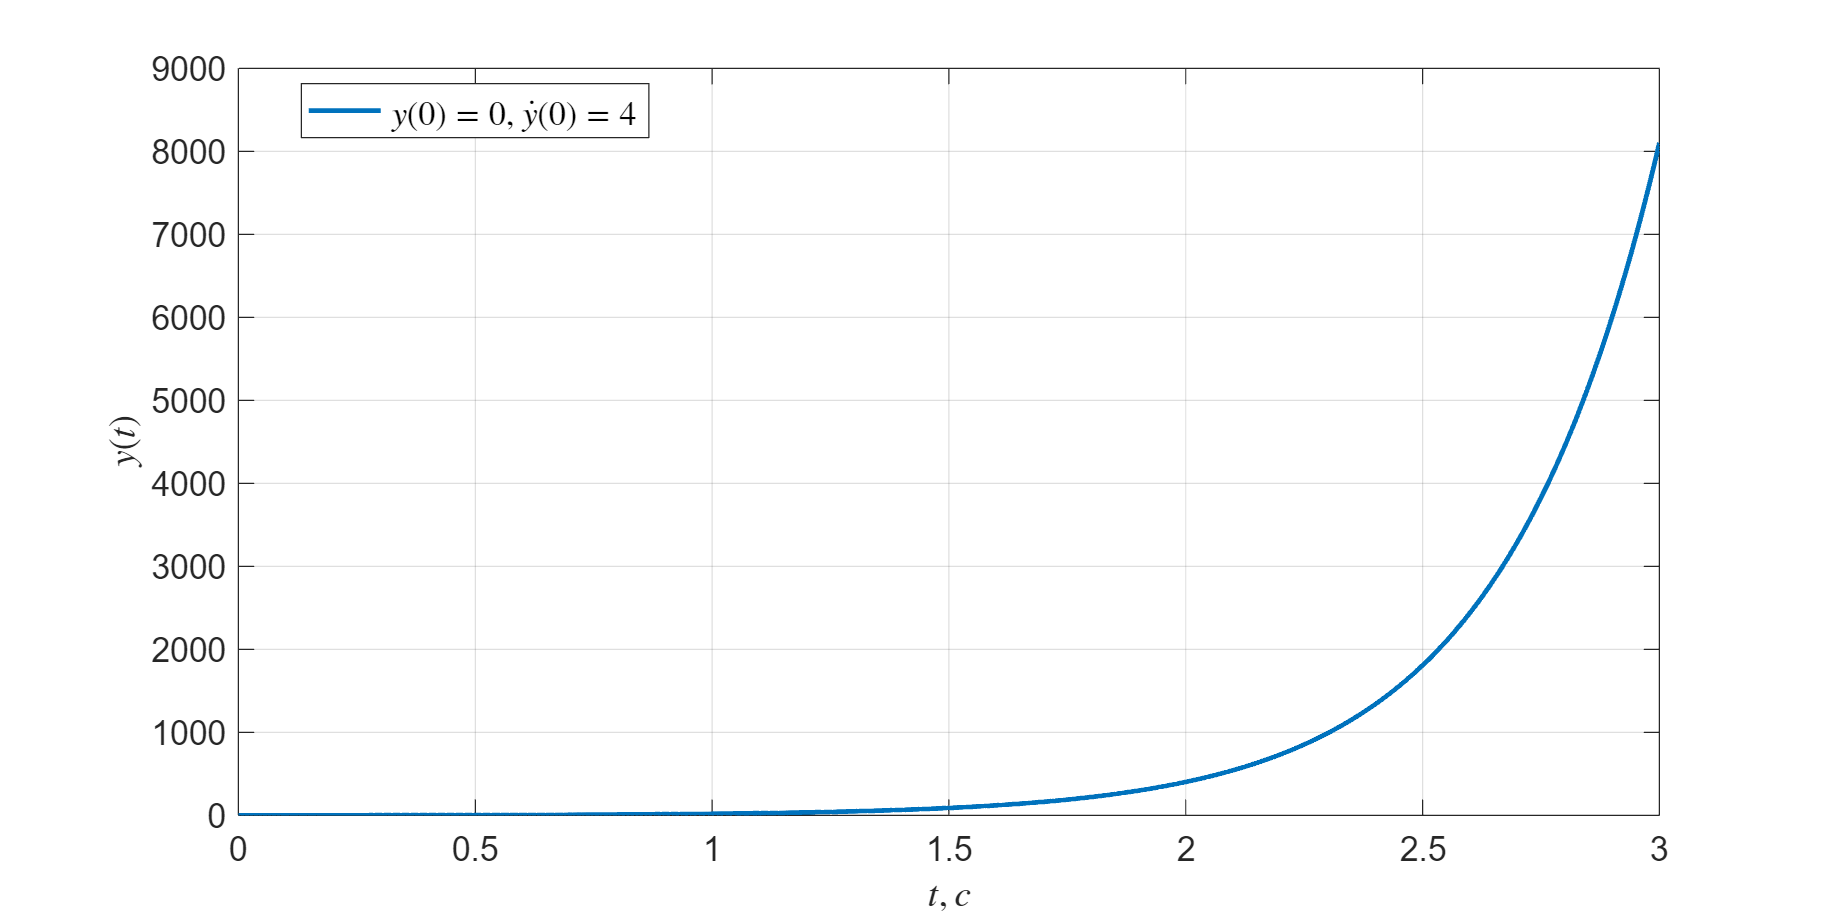

a_0 = -3;
a_1 = -2;
a_2 = 1;

simtime = 3;
plot_1 = sim("lab4_1.slx", simtime);
plot(plot_1.y.Time, plot_1.y.Data, LineWidth=2, LineStyle="-", ...
            DisplayName=sprintf('$y(0)=%d, \\dot{y}(0)=%d$', 0, 4))
grid on;
legend(Location="best", FontSize=14, Interpreter="latex");
xlabel("$t, c$", Interpreter="latex");
ylabel("$y(t)$", Interpreter="latex");
set(gcf, Position=[100, 100, 1200, 600]);   
set(gca, FontSize=14);
exportgraphics(gcf, "images/plot_1.png", Resolution=200)

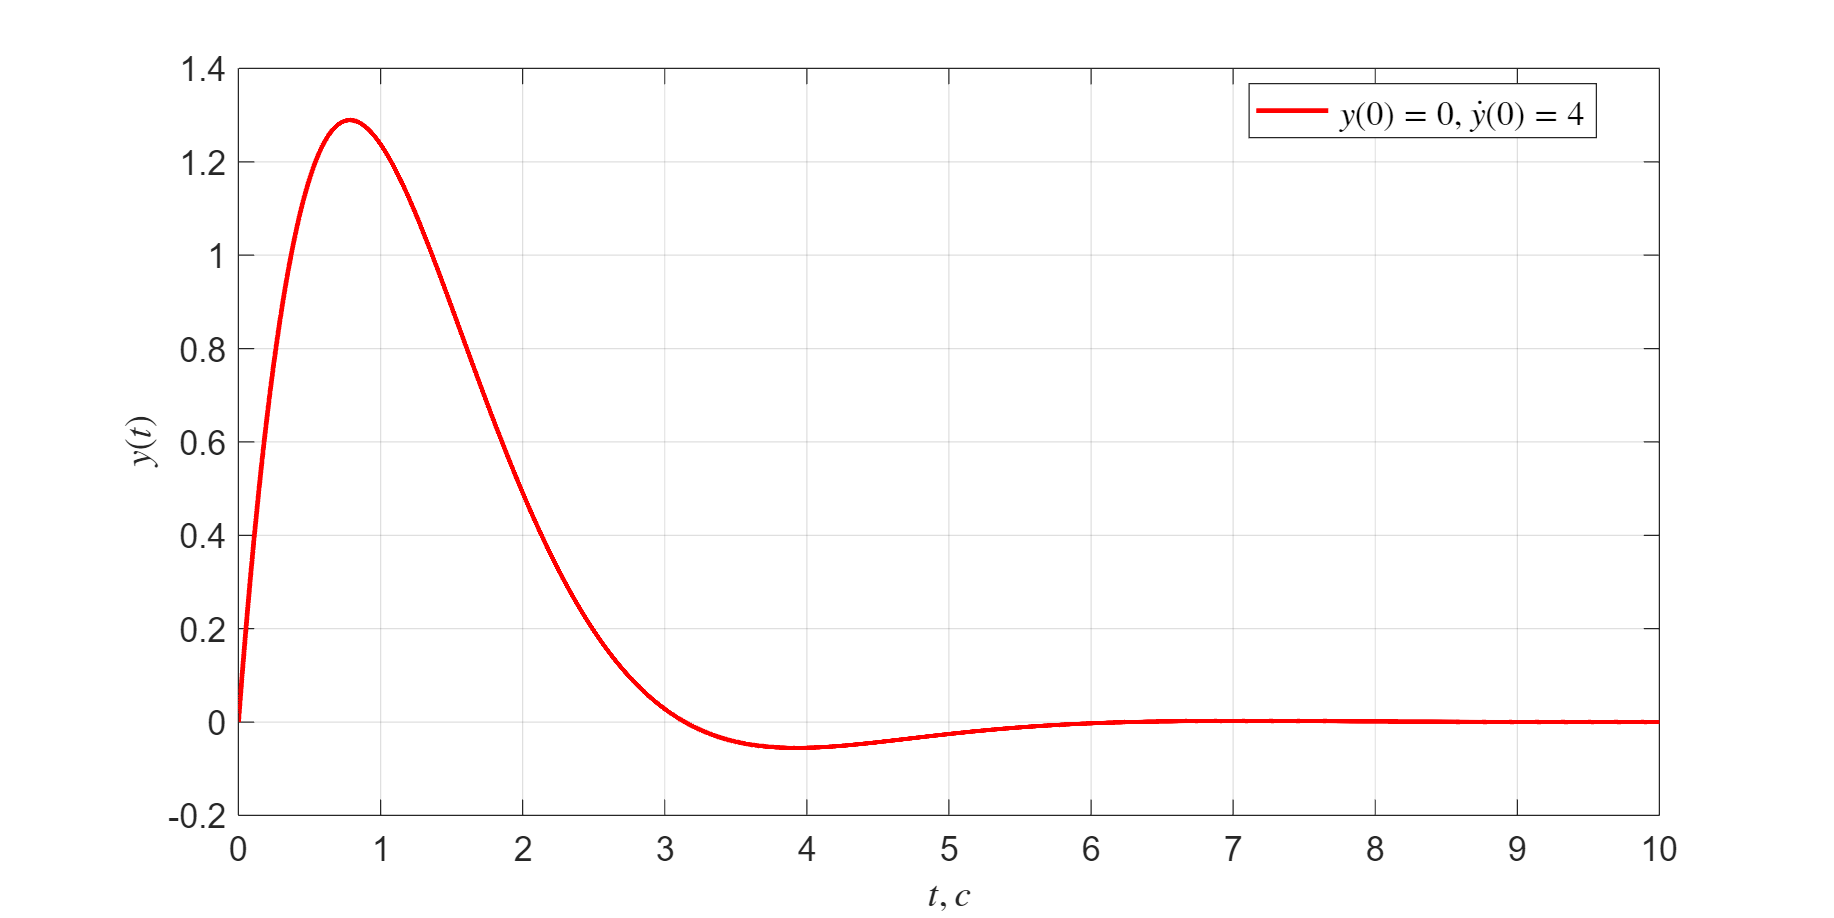

k_0 = -5;
k_1 = -4;

simtime = 10;
plot_1 = sim("lab4_1z.slx", simtime);
plot(plot_1.y.Time, plot_1.y.Data, LineWidth=2, color="red", LineStyle="-", ...
            DisplayName=sprintf('$y(0)=%d, \\dot{y}(0)=%d$', 0, 4))
grid on;
legend(Location="best", FontSize=14, Interpreter="latex");
xlabel("$t, c$", Interpreter="latex");
ylabel("$y(t)$", Interpreter="latex");
set(gcf, Position=[100, 100, 1200, 600]);   
set(gca, FontSize=14);
exportgraphics(gcf, "images/plot_1z.png", Resolution=200)

# Задание 2

\section{Задача стабилизации с реальным дифференцирующим звеном}

Модифицируем замкнутую систему из **Задания 1**, заменив аппроксимацию производной $\dot{y}(t)$ на передаточную функцию вида


$$W_{\text{р.дифф.}}(p) = \frac{p}{T p + 1}. \quad (3)$$


Определим аналитически критические значения параметра $T$, при которых система становится неустойчивой для выбранных ранее $k_0$ и $k_1$.

Осуществим аналогичное **Заданию 1** моделирование движения замкнутой системы $y_{\text{з}}(t)$ для нескольких различных значений параметра $T$, соответствующих устойчивой

системе. Приведем соответствующие графики выхода $y(t)$ и сопоставим их между собой и с результатом моделирования замкнутой системы из **Задания 1**. Сделаем выводы.

Модифицируем схему (см. рис. ???).

???РИСУНОК???

Найдём значения $T$, при которых система становится неустойчивой:


$$a_2p^2y+a_1py+a_0y=k_0y+k_1\frac{p}{T p + 1}y,\\
a_2Tp^3y+a_2p^2y+a_1Tp^2y+(a_1-k_1-k_0T)py+a_0Tpy+(a_0-k_0)y=0,\\
Tp^3y+(1-2T)p^2y-(2+k_1+k_0T+3T)py-(3+k_0)y=0,\\
T\dddot{y}+(1-2T)\ddot{y}+2(1+T)\dot{y}+2y=0$$


Система однозначно неустойчива при отрицательных коэффициентах, то есть при: $T<0,\quad T>\frac{1}2},\QUAD $.

Воспользуемся критерием Гурвица для определения областей устойчивости. Матрица Гурвица:


$$A = \pmatrix{ 1 - 2T & 2 & 0 \cr T & 2(1 + T) & 0 \cr 0 & 1 - 2T & 2}$$


Ведущие угловые миноры матрицы Гурвица:


$$\Delta_1 = 1 - 2T,\\
\Delta_2 = 2 - 4T - 4T^2=-4\left(T+\frac{1+\sqrt{3}}{2}\right)\left(T+\frac{1-\sqrt{3}}{2}\right),\\
\Delta_3 =2\Delta_2 = 4 - 8T - 8T^2=-8\left(T+\frac{1+\sqrt{3}}{2}\right)\left(T+\frac{1-\sqrt{3}}{2}\right)$$


Следовательно, система ассимптотически устойчива при: $T\in\left(0, \frac{1+\sqrt{3}}{2}\right)$.

Выполним моделирование при различных $T$, соответствущих устойчивости система (см. рис. ???).

???РИСУНОК???

**Выводы**

В данном задании мы заменили прямое численное дифференцирование на передаточную функцию с параметром $T$ и выполнили моделирование для различных его значений, соответствующих устойчивой системе. Это временной параметр, который отражает скорость реакции системы не воздействие. При меньших значениях $T$ система быстрее приходит к установившемуся значению, однако, чем ближе $T$ к нулю, тем ближе мы и к физической нереализуемости системы, так как при $T=0$ числитель$W_{\text{р.дифф.}}(p) = \frac{p}{T p + 1}$ становится больше знаменателя. При увеличении $T$ увеличивается колебательность при переходном процессе и он длится дольше. При $T$, близком к нулю, мы видим процесс, очень похожий на использование дифференцирования.

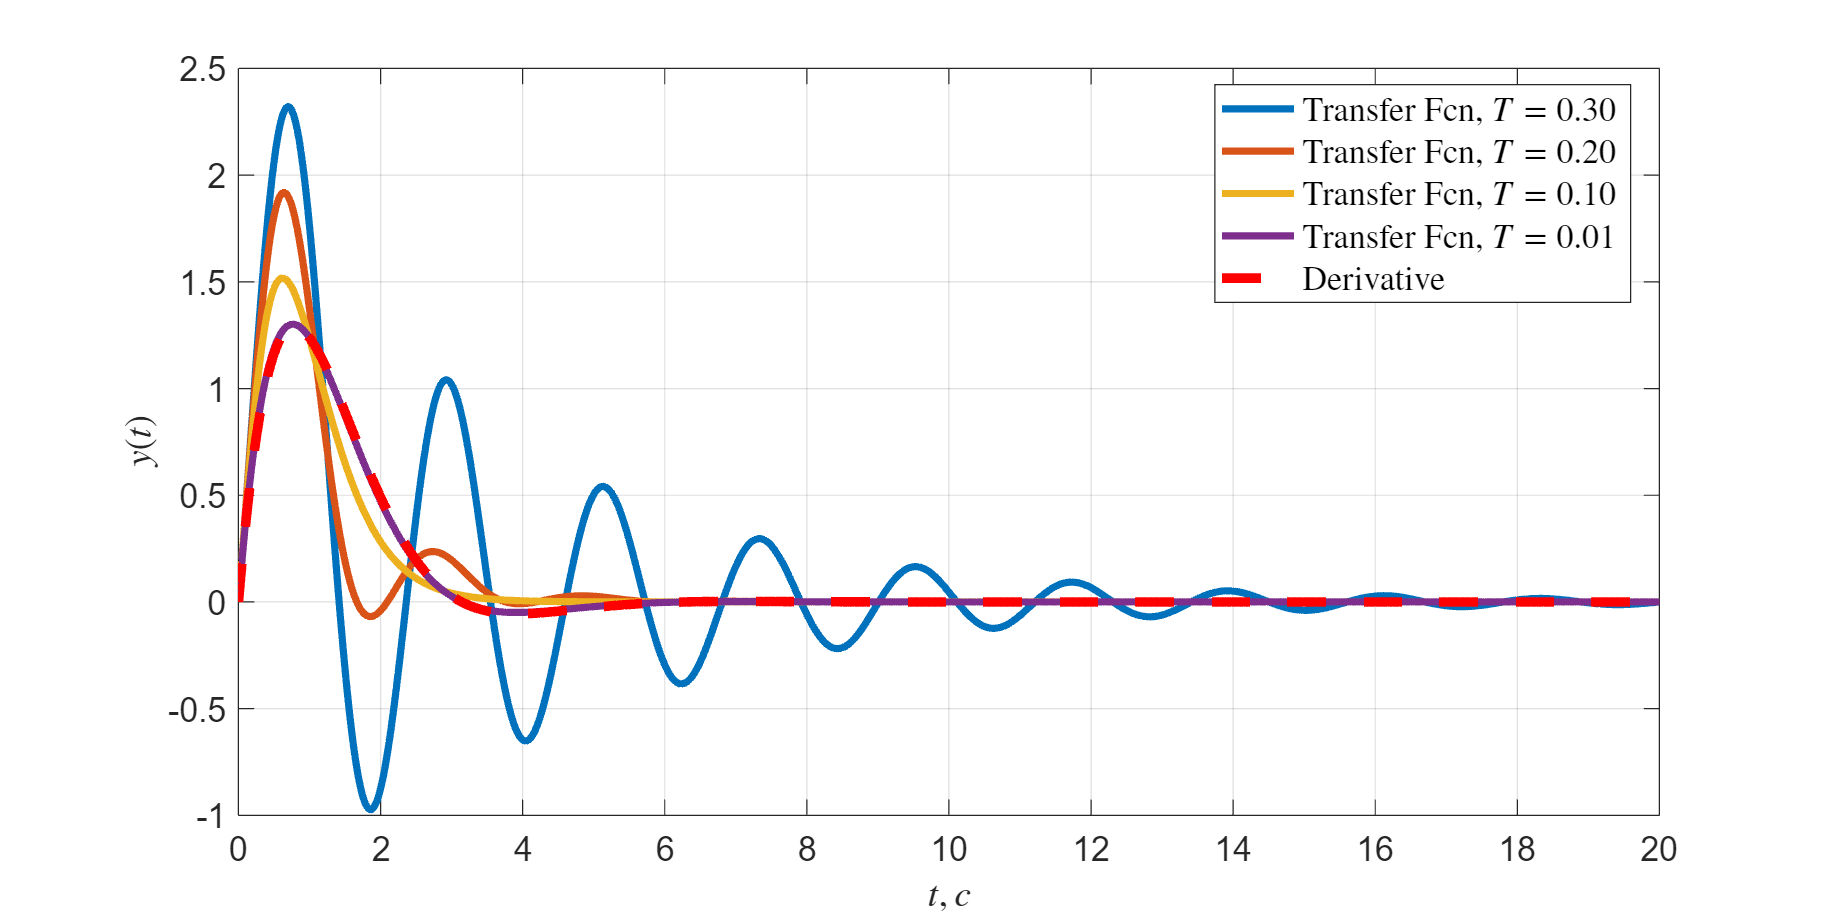

T_arr = [0.3, 0.2, 0.1, 0.01];
simtime = 20;
for i = 1:length(T_arr)
    T = T_arr(i);
    plot_2 = sim("lab4_2z.slx", simtime);
    plot(plot_2.y.Time, plot_2.y.Data, LineWidth=3, LineStyle="-", ...
                DisplayName=sprintf('Transfer Fcn, $T=%.2f$', T))
    hold on;
end
plot_1 = sim("lab4_1z.slx", simtime);
plot(plot_1.y.Time, plot_1.y.Data, LineWidth=4, color="red", LineStyle="--", ...
            DisplayName='Derivative')
hold on;

grid on;
legend(Location="best", FontSize=14, Interpreter="latex");
xlabel("$t, c$", Interpreter="latex");
ylabel("$y(t)$", Interpreter="latex");
set(gcf, Position=[100, 100, 1200, 600]);   
set(gca, FontSize=14);
hold off;
exportgraphics(gcf, "images/plot_2z.png", Resolution=200)

# Задание 3

\section{Задача слежения для системы с астатизмом нулевого порядка (П-регулятор)}

Рассмотрим замкнутую систему, заданную структурной схемой на рисунке ???, где


$$H(s) = k$$


— пропорциональный регулятор. Варианты передаточной функции объекта управления $W(s)$ и характеристики задающего воздействия $g(t)$ приведены в **Таблице 1 **инструкции по выполнению лабораторной работы. Зададимся не менее чем тремя значениями параметра $k$, которые бы обеспечивали асимптотически устойчивую замкнутую систему.

Исследуем стационарный режим работы при $g(t) = A$: выполним моделирование для выбранных значений $k$, а также аналитически определим предельное значение ошибки $e_{уст}$ для каждого значения $k$. Сопоставим результаты между собой и сделаем выводы о влиянии величины $k$.

Исследуем режим движения с постоянной скоростью при $g(t) = V t$: выполним моделирование для выбранных значений $k$. Сопоставим результаты между собой и сделаем выводы о влиянии величины $k$.

???РИСУНОК???

Возьмём из таблицы для варианта 27 передаточную функцию и параметры управляющего воздействия:


$$W(s)=\frac{1}{4s^2+0.6s+1},\quad A=3,\quad Vt=2.5t$$


Передаточная функция замкнутой системы: $W_{g\rightarrow y}(s)=\frac{W(s)W_{\text{рег}}(s)}{1+W(s)W_{\text{рег}}(s)}$, где $W(s)W_{\text{рег}}(s)$ - передаточная функция разомкнутой системы.


$$W_{g\rightarrow y}(s)=\frac{W(s)W_{\text{рег}}(s)}{1+W(s)W_{\text{рег}}(s)}=
\frac{\frac{k}{4s^2+0.6s+1}}{1+\frac{k}{4s^2+0.6s+1}}=
\frac{k}{4s^2+0.6s+1+k}$$


Найдем такие $k$, при которых замкнутая система является ассимптотически устойчивой.


$$4s^2+0.6s+1+k=0,\quad s_{1,2}=\frac{-0.6\pm\sqrt{0.36-4\cdot4(1+k)}}{8}=\frac{-0.6\pm\sqrt{-15.64-16k}}{8}=\\
=-0.075\pm\frac{\sqrt{-(15.64+16k)}}{8}\Rightarrow \text{Re}\left[\sqrt{-(15.64+16k)}\right]<0.6\Rightarrow k>-1$$


При $k>-1$ полюса передаточной функции будут отрицательными и мы получаем нужную устойчивость.

Зададимся значениями $k=\{0.5, 2, 29\}$.

Проведем исследование для двух режимов работы.

**Стационарный: **$G(s)=\frac{A}{s}$.

Аналитически определим предельное значение ошибки $e_{уст}$ для каждого значения $k$:

Ошибка слежения:


$$E(s)=\frac{1}{1+W(s)W_{\text{рег}}(s)}G(s)=\frac{1}{1+\frac{k}{4s^2+0.6s+1}}\frac{A}{s}=\frac{A(4s^2+0.6s+1)}{s(4s^2+0.6s+1+k)}$$


Согласно теореме о конечном значении, если все полюса $s\cdot E(s)$ имеют отрицательную вещественную часть, $\lim_{t\rightarrow+\infty}{y(t)=\lim_{s\rightarrow0}{sY(s)}$.

$s\cdot E(s)=\frac{A(4s^2+0.6s+1)}{4s^2+0.6s+1+k}$, полюса данной передаточной функции отрицательны, так как ранее мы уже подбирали диапазон $k$, соответствующий отрицательным полюсам передаточной функции с таким же знаменателем. Можем применнить теорему о конечном значении и найти установившуюся ошибку:


$$e_{\text{уст}}=\lim_{s\rightarrow0}{s\cdot E(s)}=\lim_{s\rightarrow0}{\frac{A(4s^2+0.6s+1)}{4s^2+0.6s+1+k}}=\frac{A(4\cdot0^2+0.6\cdot0+1)}{4\cdot0^2+0.6\cdot0+1+k}=\frac{A}{1+k}$$


Рассчитаем для каждого $k$:

- 
$$k=0.5,\quad e_{\text{уст}}=\frac{3}{1+0.5}=2$$


- 
$$k=2,\quad e_{\text{уст}}=\frac{3}{1+2}=1$$


- 
$$k=29,\quad e_{\text{уст}}=\frac{3}{1+29}=0.1$$


Выполним моделирование. Структурная схема представлена на рис. ???.

???РИСУНОК???

Графики входа и выходов на рис. ???.

???РИСУНОК???

Графики ошибки на рис. ???.

???РИСУНОК???

Как мы видим из полученных графиков, при увеличении $k$ уменьшается установившаяся ошибка, но растёт перерегулирование и колебательность системы.

**Движение с постоянной скоростью: **$G(s)=\frac{V}{s^2}$.

Выполним моделирование. Структурная схема представлена на рис. ???.

???РИСУНОК???

Графики входа и выходов на рис. ???.

???РИСУНОК???

Графики ошибки на рис. ???.

???РИСУНОК???

Из графиков видно, что следить за таким входным воздействием у пропорционального регулятора уже не получается - ошибка растет линейно (с точностью аппроксимации функции ошибки). При увеличении $k$ ошибка накапливается медленнее, но при $t\rightarrow\infty$ она всё равно уйдет в бесконечность из-за недостающего порядка астатизма.

**Выводы**

В данном задании мы исследовали пропорциональный регулятор. Для анализа системы было удобно использовать теорему о конечном значении.

При исследовании стационарного режима были аналитически получены значения установившейся ошибки, которые подтверждаются результатами моделирования. Увеличение коэффициента усиления $k$ приводит к уменьшению установившейся ошибки слежения. Однако вместе с этим заметно возрастает перерегулирование и колебательность переходного процесса, что ухудшает качество регулирования и может ограничивать максимально допустимое значение $k$ в практических условиях.

При исследовании режима движения с постоянной скоростью показано, что пропорциональный регулятор не обеспечивает нулевой или фиксированной установившейся ошибки при линейно растущем задающем воздействии. Ошибка увеличивается со временем, а увеличение коэффициента усиления лишь уменьшает скорость её нарастания, но не устраняет её полностью. Это объясняется тем, что система с П-регулятором обладает **нулевым порядком астатизма**, следовательно, она способна компенсировать только ступенчатые воздействия (с точностью до фиксированной установившейся ошибки), но не линейно (и быстрее) растущие.

Таким образом, использование пропорционального регулятора является недостаточным для задач слежения за возрастающим сигналом, но можно использовать для слежения за константным там, где можно допустить небольшую установившуюся ошибку.

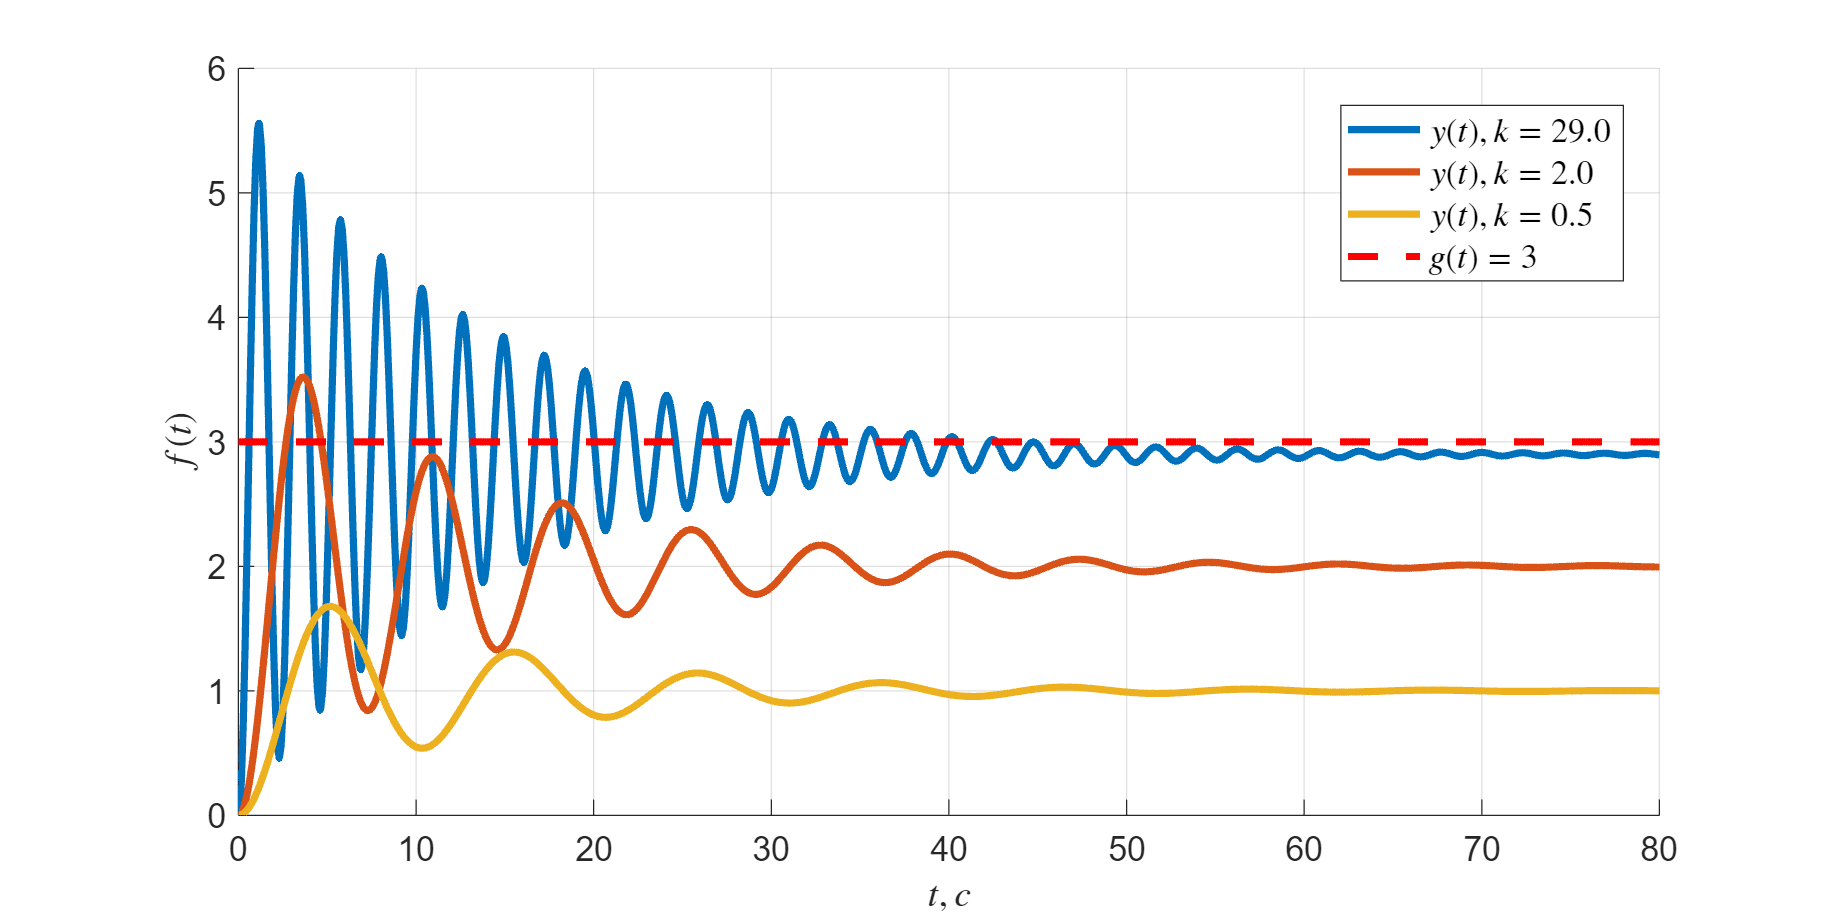

k_arr = [ 29, 2, 0.5 ];
A = 3;
V = 2.5;

simtime = 80;
figure;
set(gcf,'AutoResizeChildren','off');
hold on;

for i = 1:length(k_arr)
    k = k_arr(i);
    plot_3 = sim("lab4_31.slx", simtime);
    plot(plot_3.y.Time, plot_3.y.Data, LineWidth=3, LineStyle="-", ...
                DisplayName=sprintf('$y(t), k=%.1f$', k))
    hold on;
end
plot_31 = sim("lab4_31.slx", simtime);
plot(plot_31.g.Time, plot_31.g.Data, LineWidth=3, color="red", LineStyle="--", ...
            DisplayName='$g(t)=3$')
hold on;

grid on;
legend(Location="best", FontSize=14, Interpreter="latex");
xlabel("$t, c$", Interpreter="latex");
ylabel("$f(t)$", Interpreter="latex");
set(gcf, Position=[100, 100, 1200, 600]);   
set(gca, FontSize=14);

drawnow;
exportgraphics(gcf, "images/plot_31.png", Resolution=200)
hold off;

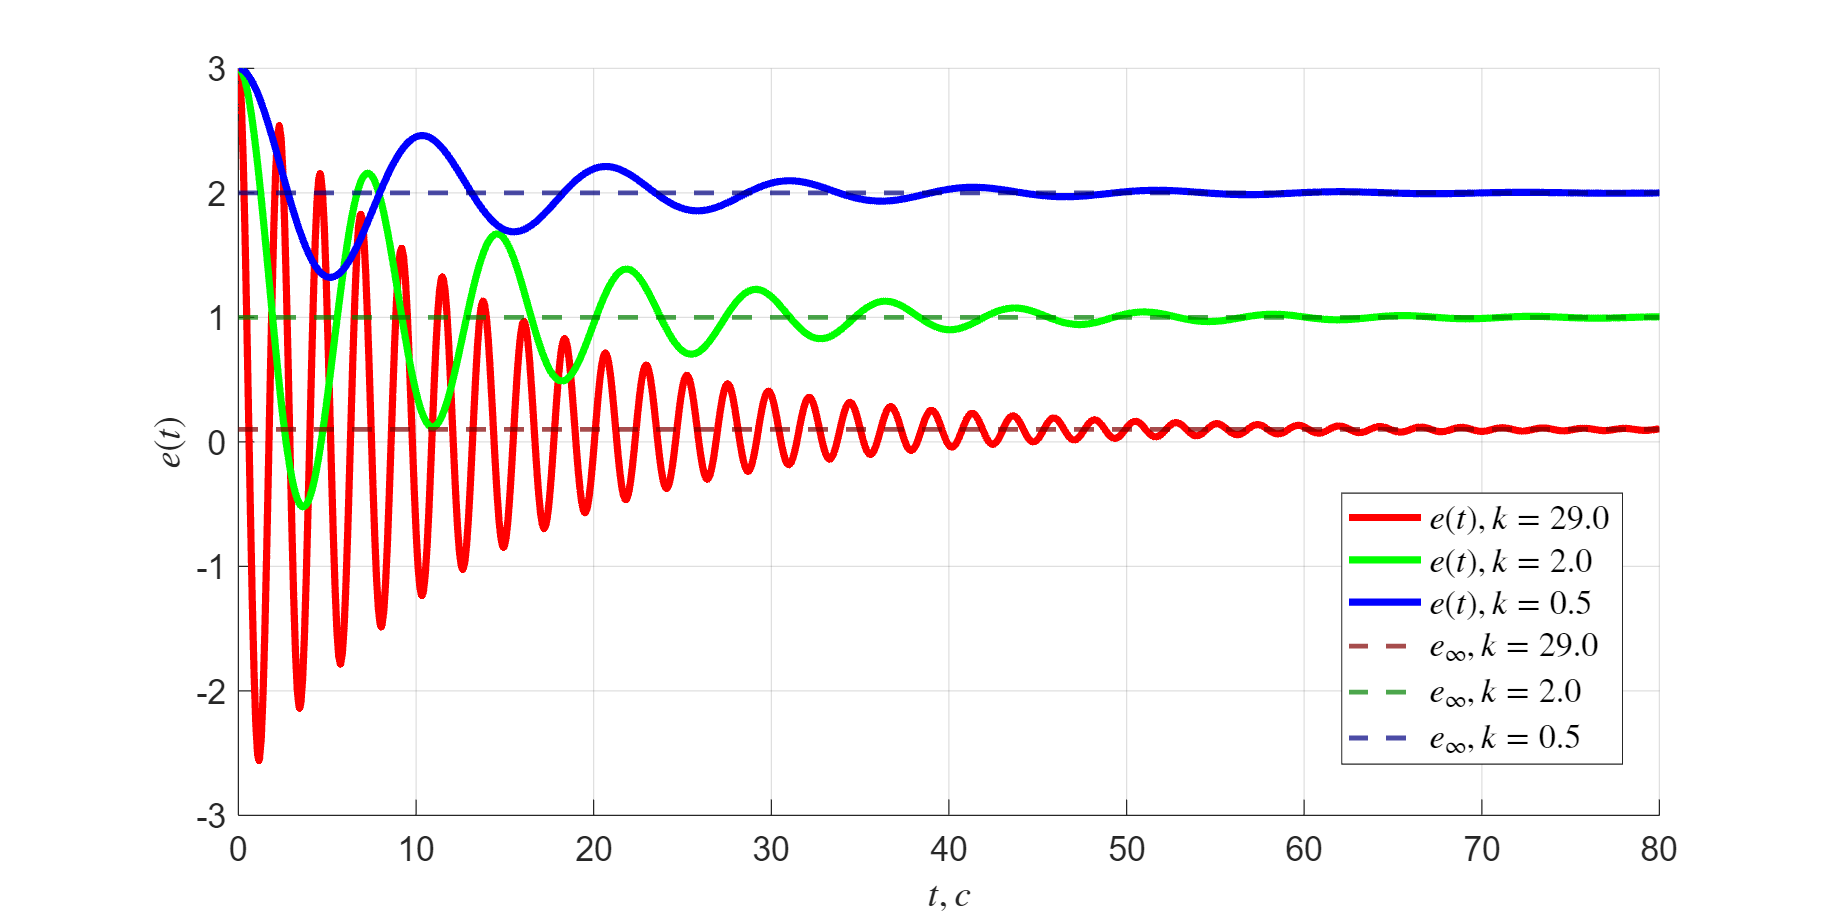

e_inf = [0.1, 1, 2]; 

figure;
set(gcf,'AutoResizeChildren','off');
hold on;
colors = hsv(length(k_arr));

for i = 1:length(k_arr)
    k = k_arr(i);
    plot_3 = sim("lab4_31.slx", simtime);
    plot(plot_3.e.Time, plot_3.e.Data, LineWidth=3, LineStyle="-", ...
                DisplayName=sprintf('$e(t), k=%.1f$', k), Color=colors(i,:))
    darkColor = colors(i,:) * (1 - 0.5);

    yline(e_inf(i), '--', Color=darkColor, LineWidth=2, ...
        DisplayName=sprintf('$e_{\\infty}, k=%.1f$', k));

    hold on;
end

grid on;
legend(Location="best", FontSize=14, Interpreter="latex");
xlabel("$t, c$", Interpreter="latex");
ylabel("$e(t)$", Interpreter="latex");
set(gcf, Position=[150, 150, 1200, 600]);
set(gca, FontSize=14);

drawnow;
exportgraphics(gcf, "images/plot_31_err.png", Resolution=200)
hold off;

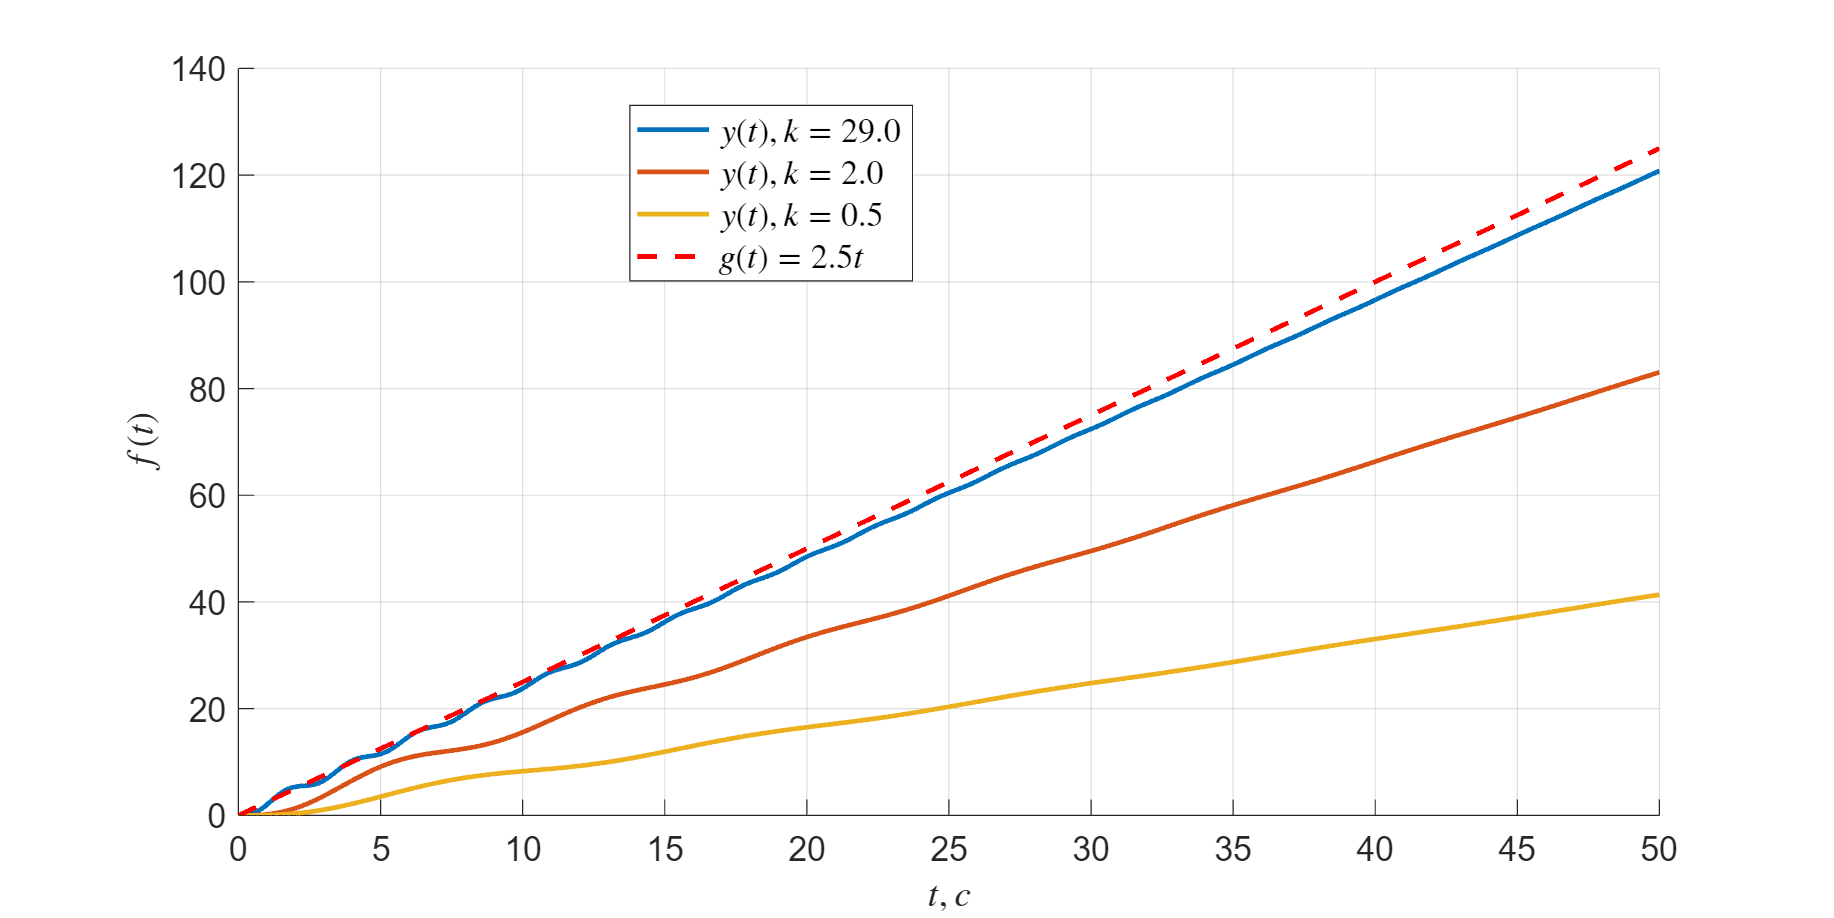

simtime = 50;
figure;
set(gcf,'AutoResizeChildren','off');
hold on;

for i = 1:length(k_arr)
    k = k_arr(i);
    plot_3 = sim("lab4_32.slx", simtime);
    plot(plot_3.y.Time, plot_3.y.Data, LineWidth=2, LineStyle="-", ...
                DisplayName=sprintf('$y(t), k=%.1f$', k))
    hold on;
end
plot_31 = sim("lab4_32.slx", simtime);
plot(plot_31.g.Time, plot_31.g.Data, LineWidth=2, color="red", LineStyle="--", ...
            DisplayName='$g(t)=2.5t$')
hold on;

grid on;
legend(Location="best", FontSize=14, Interpreter="latex");
xlabel("$t, c$", Interpreter="latex");
ylabel("$f(t)$", Interpreter="latex");
set(gcf, Position=[100, 100, 1200, 600]);   
set(gca, FontSize=14);

drawnow;
exportgraphics(gcf, "images/plot_32.png", Resolution=200)
hold off;

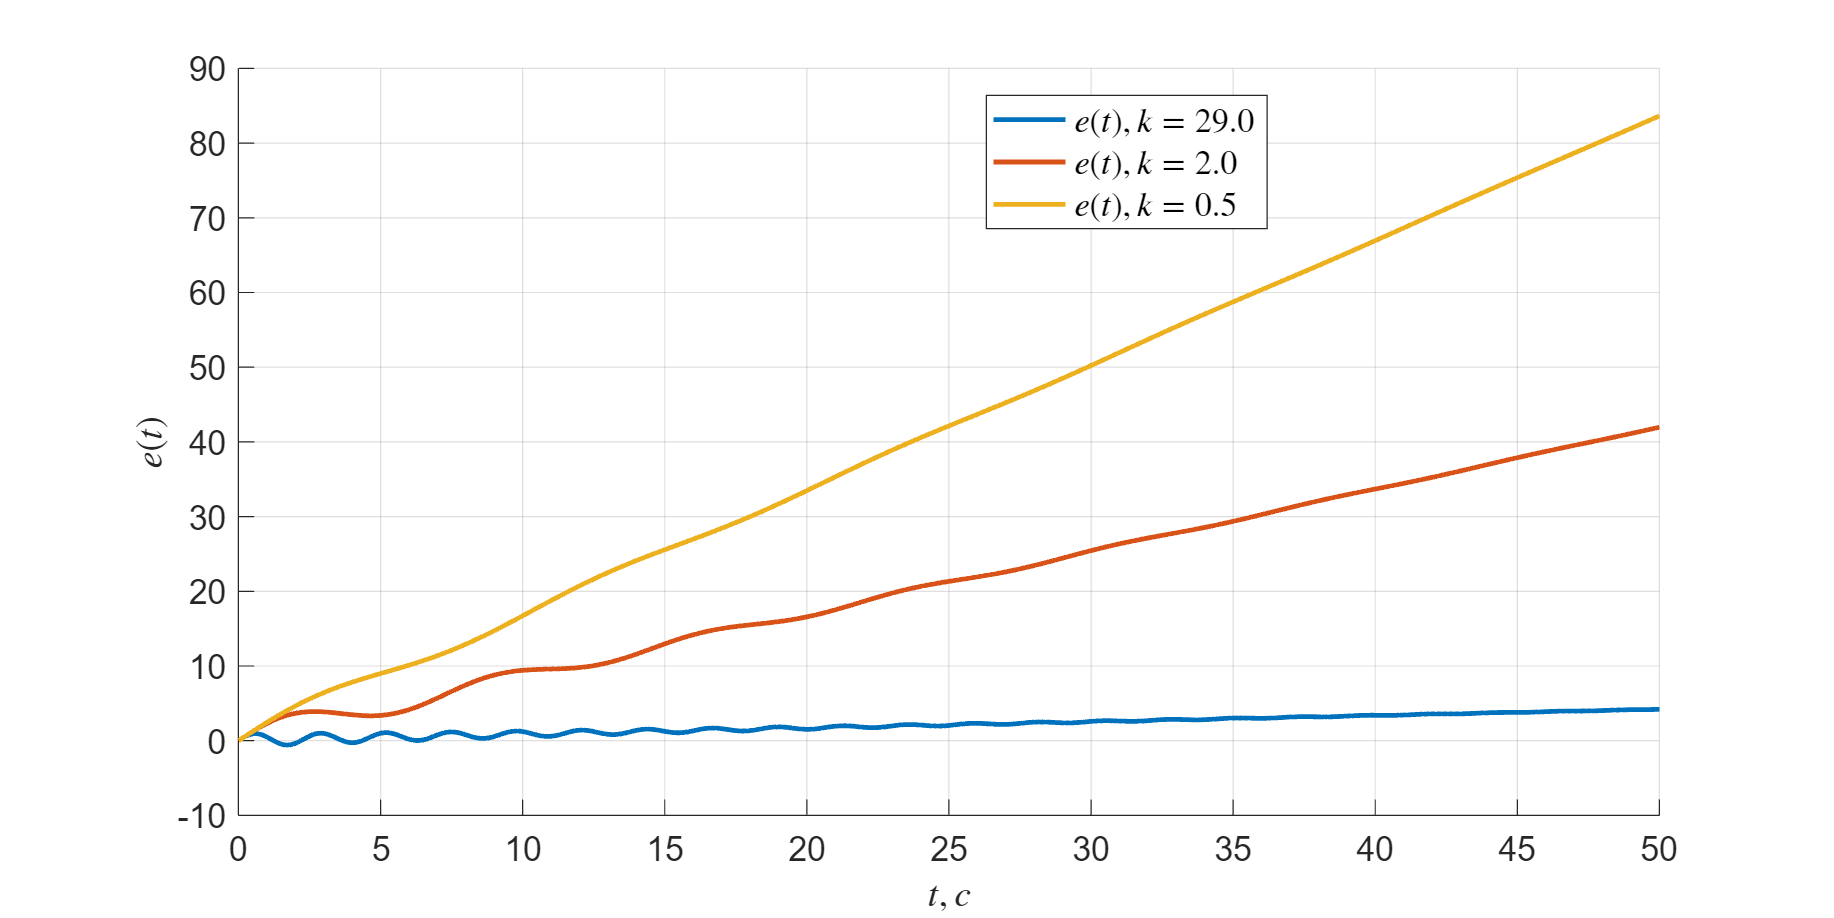

figure;
set(gcf,'AutoResizeChildren','off');
hold on;

for i = 1:length(k_arr)
    k = k_arr(i);
    plot_3 = sim("lab4_32.slx", simtime);
    plot(plot_3.e.Time, plot_3.e.Data, LineWidth=2, LineStyle="-", ...
                DisplayName=sprintf('$e(t), k=%.1f$', k))

    hold on;
end

grid on;
legend(Location="best", FontSize=14, Interpreter="latex");
xlabel("$t, c$", Interpreter="latex");
ylabel("$e(t)$", Interpreter="latex");
set(gcf, Position=[150, 150, 1200, 600]);
set(gca, FontSize=14);

drawnow;
exportgraphics(gcf, "images/plot_32_err.png", Resolution=200)
hold off;

# Задание 4

\section{Задача слежения для системы с астатизмом первого порядка (И-регулятор)}

Рассмотрим замкнутую систему, заданную структурной схемой на рисунке ???ВЫШЕ???, где


$$H(s) = \frac{k}{s}$$


— интегральный регулятор. Варианты передаточной функции объекта управления $W(s)$ и характеристики задающего воздействия $g(t)$ приведены в  **Таблице 1 **инструкции по выполнению лабораторной работы. Зададимся не менее чем тремя значениями параметра $k$, которые бы обеспечивали асимптотически устойчивую замкнутую систему.

Исследуем стационарный режим работы при $g(t) = A$: выполним моделирование для выбранных значений $k$, а также аналитически определим предельное значение ошибки $e$ для каждого значения $k$. Сопоставим результаты между собой и сделаем выводы.

Исследуем режим движения с постоянной скоростью при $g(t) = V t$: выполним моделирование для выбранных значений $k$, а также аналитически определим предельное значение ошибки $e$ для каждого значения $k$. Сопоставим результаты между собой и сделаем выводы.

Исследуем режим движения с постоянным ускорением при $g(t) = \frac{a t^2}{2}$: выполним моделирование для выбранных значений $k$. Сопоставим результаты между собой и сделаем выводы.

Возьмём из таблицы для варианта 27 передаточную функцию и параметры управляющего воздействия:


$$W(s) = \frac{1}{4s^2 + 0.6s + 1}, \quad A = 3, \quad V = 2.5, \quad \frac{a}{2} = 0.4$$


Передаточная функция замкнутой системы:


$$W_{g \rightarrow y}(s) = \frac{W(s) H(s)}{1 + W(s) H(s)} = \frac{\frac{k}{s} \cdot \frac{1}{4s^2+0.6s+1}}{1 + \frac{k}{s} \cdot \frac{1}{4s^2+0.6s+1}} = \frac{k}{4s^3 + 0.6 s^2 + s + k}$$


Найдем такие $k$, при которых замкнутая система является ассимптотически устойчивой.

$4s^3 + 0.6s^2 + s + k = 0$, воспользуемся критерием Гурвица, матрица Гурвица:


$$A=\pmatrix{0.6 & k & 0 \cr4 & 1 & 0 \cr0 & 0.6 & k}$$


Ведущие угловые миноры матрицы Гурвица: $\Delta_1 = 0.6,\quad \Delta_2  = 0.6 - 4k,\quad \Delta_3 = k \cdot \Delta_2 = k(0.6 - 4k)$

Следовательно, система ассимптотически устойчива при: $k\in \left(0,0.15)$.

Зададимся значениями $k=\{0.125, 0.07, 0.02\}$.

Проведем исследование для трёх режимов работы.

**Стационарный: **$G(s)=\frac{A}{s}$.

Аналитически определим предельное значение ошибки $e_{уст}$ для каждого значения $k$:

Ошибка слежения:


$$E(s)=\frac{1}{1+W(s)H(s)}G(s) = \frac{s(4s^2 + 0.6 s + 1)}{4s^3 + 0.6 s^2 + s + k} \cdot \frac{A}{s} = \frac{12s^2 + 1.8 s + 3}{4s^3 + 0.6 s^2 + s + k}$$


Согласно теореме о конечном значении, если все полюса имеют отрицательную вещественную часть, $\lim_{t\rightarrow+\infty}{y(t)=\lim_{s\rightarrow0}{sY(s)}$.

$s\cdot E(s)=\frac{s(12s^2 + 1.8 s + 3)}{4s^3 + 0.6 s^2 + s + k}$, полюса данной передаточной функции отрицательны, так как ранее мы уже подбирали диапазон $k$, соответствующий отрицательным полюсам передаточной функции с таким же знаменателем. Можем применнить теорему о конечном значении и найти установившуюся ошибку:


$$e_{\text{уст}}=\lim_{s\rightarrow0}{s\cdot E(s)}=\lim_{s \to 0}{\frac{s(12s^2 + 1.8 s + 3)}{4s^3 + 0.6 s^2 + s + k}}=\frac{0\cdot(12\cdot0^2 + 1.8 \cdot0 + 3)}{4\cdot0^3 + 0.6 \cdot0^2 + s + k}=0$$


Для любых $k$ установившаяся ошибка нулевая.

Выполним моделирование. Структурная схема представлена на рис. ???.

???РИСУНОК???

Графики входа и выходов на рис. ???.

???РИСУНОК???

Графики ошибки на рис. ???.

???РИСУНОК???

Видим, что $y(t)$ сходится к задающему воздействию при любых $k$, но при повышении $k$ возрастает колебательность переходного процесса. При уменьшении $k$ увеличивается время переходного процесса. Золотая середина из выбранных $k$ это $0.07$ - при нём колебательность незначительная и время переходного процесса наименьшее. У слишком маленьких значений $k$ время переходного процесса увеличивается из-за высокой колебательности.

**Движение с постоянной скоростью: **$G(s)=\frac{V}{s^2}$.

Аналитически определим предельное значение ошибки $e_{уст}$ для каждого значения $k$:

Ошибка слежения:


$$E(s)=\frac{1}{1+W(s)H(s)}G(s)= \frac{s(4s^2 + 0.6 s + 1)}{4s^3 + 0.6 s^2 + s + k} \cdot \frac{V}{s^2} = \frac{V(4s^2 + 0.6 s + 1)}{s(4s^3 + 0.6 s^2 + s + k)}$$


Согласно теореме о конечном значении, если все полюса $s\cdot E(s)$ имеют отрицательную вещественную часть, $\lim_{t\rightarrow+\infty}{y(t)=\lim_{s\rightarrow0}{sY(s)}$.

$s\cdot E(s)=\frac{V(4s^2 + 0.6 s + 1)}{4s^3 + 0.6 s^2 + s + k}$, полюса данной передаточной функции отрицательны, так как ранее мы уже подбирали диапазон $k$, соответствующий отрицательным полюсам передаточной функции с таким же знаменателем. Можем применнить теорему о конечном значении и найти установившуюся ошибку:


$$e_{\text{уст}}=\lim_{s\rightarrow0}{s\cdot E(s)}=\lim_{s\rightarrow0}{\frac{V(4s^2 + 0.6 s + 1)}{4s^3 + 0.6 s^2 + s + k}}=\frac{V(4\cdot0^2 + 0.6\cdot0 + 1)}{4\cdot0^3 + 0.6\cdot0^2 + 0 + k}=\frac{V}{k}$$


Рассчитаем для каждого $k$:

- 
$$k=0.02,\quad e_{\text{уст}}=\frac{2.5}{0.02}=125$$


- 
$$k=0.07,\quad e_{\text{уст}}=\frac{2.5}{0.07}\approx35.7$$


- 
$$k=0.125,\quad e_{\text{уст}}=\frac{2.5}{0.125}=20$$


Выполним моделирование. Структурная схема представлена на рис. ???.

???РИСУНОК???

Графики входа и выходов на рис. ???.

???РИСУНОК???

Графики ошибки на рис. ???.

???РИСУНОК???

Как мы видим из полученных графиков, при увеличении $k$ уменьшается установившаяся ошибка, наблюдается незначительное повышение колебательности.

**Движение с постоянным ускорением: **$G(s)=\frac{a}{s^3}$.

Выполним моделирование. Структурная схема представлена на рис. ???.

???РИСУНОК???

Графики входа и выходов на рис. ???.

???РИСУНОК???

Графики ошибки на рис. ???.

???РИСУНОК???

Из графиков видно, что следить за таким входным воздействием у интегрального регулятора уже не получается - ошибка растет линейно (с точностью аппроксимации функции ошибки). При увеличении $k$ ошибка накапливается медленнее, но при $t\rightarrow\infty$ она всё равно уйдет в бесконечность из-за недостающего порядка астатизма.

**Выводы**

В данном задании мы исследовали интегральный регулятор. Для анализа системы, как и ранее, было удобно использовать теорему о конечном значении, а для проверки устойчивости был применен критерий Гурвица, который показал существенное ограничение на максимальный коэффициент усиления $k$.

При исследовании стационарного режима было рассчитано, что установившаяся ошибка равна нулю для любого значения коэффициента $k$ из диапазона устойчивости. Этот аналитический результат подтверждается результатами моделирования и объясняется тем, что система с И-регулятором обладает астатизмом первого порядка, что позволяет ей без ошибки отрабатывать постоянное задающее воздействие.

При исследовании режима движения с постоянной скоростью были аналитически получены значения установившейся ошибки, которые подтверждаются результатами моделирования. Увеличение коэффициента усиления $k$ приводит к уменьшению установившейся ошибки слежения. Однако вместе с этим может незначительно возрастать колебательность переходного процесса, а максимально допустимое значение $k$ жестко ограничено условиями устойчивости.

При исследовании режима движения с постоянным ускорением показано, что интегральный регулятор не обеспечивает нулевой или фиксированной установившейся ошибки. Ошибка увеличивается со временем, а увеличение коэффициента усиления лишь уменьшает скорость её нарастания, но не устраняет её полностью. Это объясняется тем, что система с И-регулятором обладает первым порядком астатизма, следовательно, она способна компенсировать без ошибки постоянные воздействия и с конечной ошибкой — линейно растущие, но не способна отработать квадратично (и быстрее) растущие воздействия.

Таким образом, использование интегрального регулятора является эффективным для задач слежения за постоянным сигналом и допустимым для сигналов, растущих с постоянной скоростью, если допустима ненулевая установившаяся ошибка, величина которой может быть уменьшена ростом $k$ в пределах устойчивости. Однако для слежения за ускоренно растущими сигналами данного регулятора недостаточно.

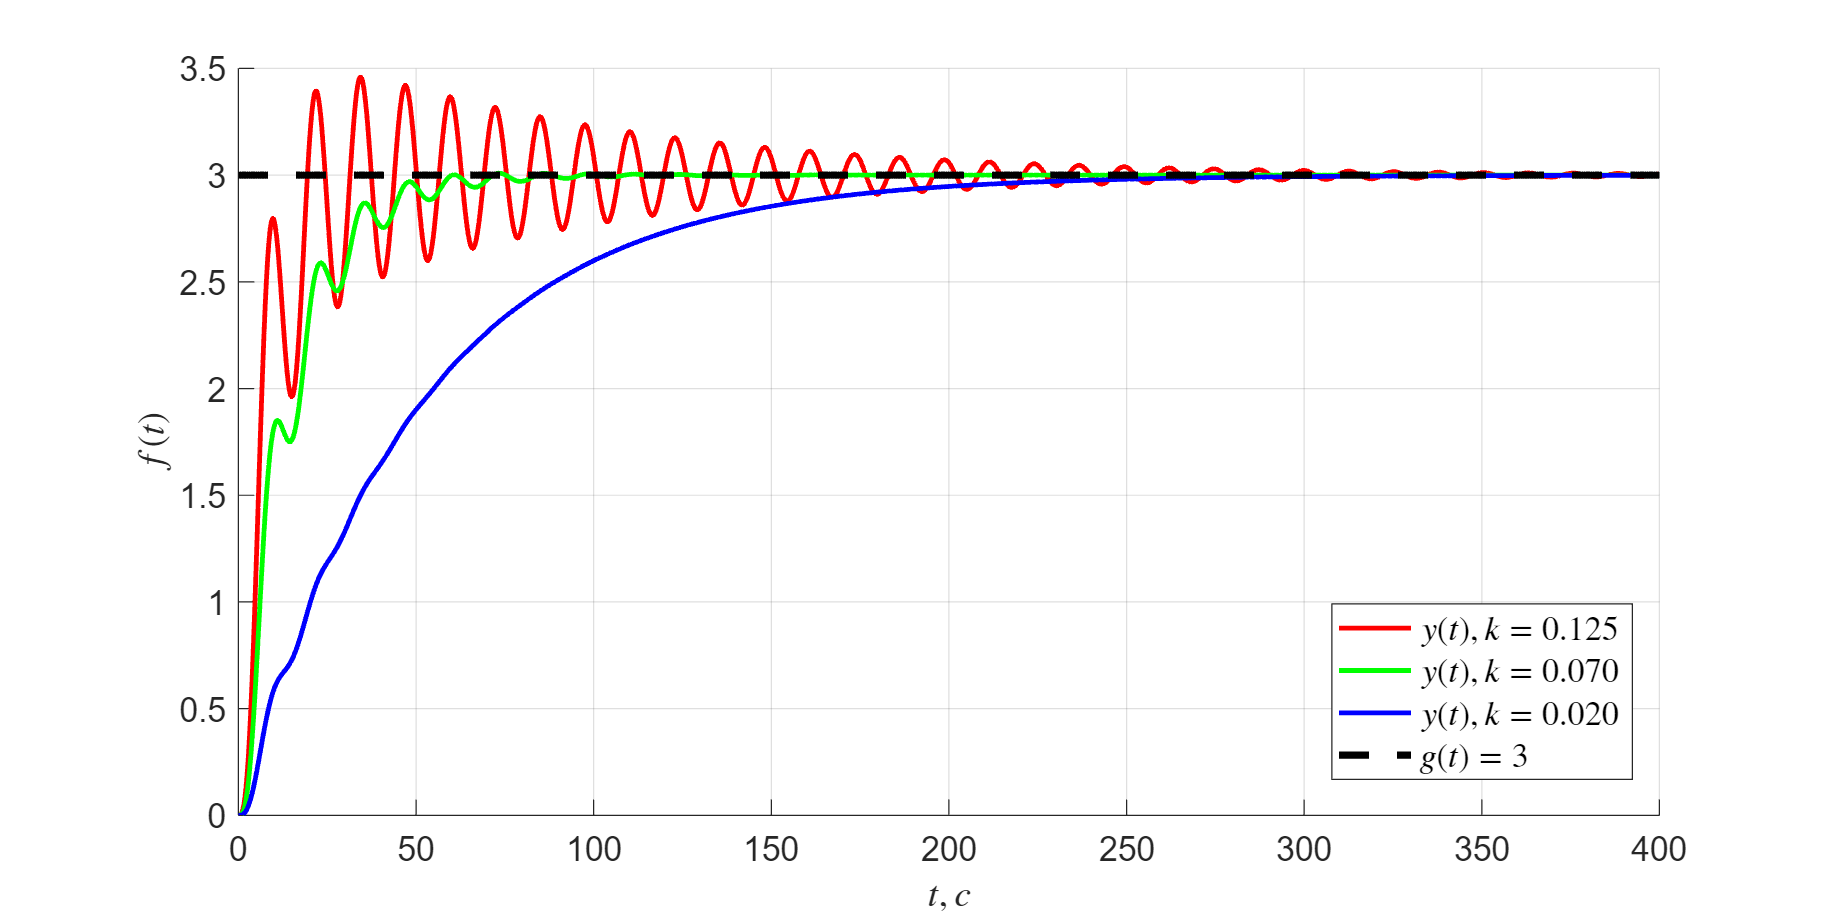

k_arr = [ 0.125, 0.07, 0.02 ];
A = 3;
V = 2.5;
half_a = 0.4;

simtime = 400;
figure;
set(gcf,'AutoResizeChildren','off');
hold on;
colors = hsv(length(k_arr));

for i = 1:length(k_arr)
    k = k_arr(i);
    plot_4 = sim("lab4_41.slx", simtime);
    plot(plot_4.y.Time, plot_4.y.Data, LineWidth=2, LineStyle="-", ...
                DisplayName=sprintf('$y(t), k=%.3f$', k), Color=colors(i,:))
    hold on;
end
plot_41 = sim("lab4_41.slx", simtime);
plot(plot_41.g.Time, plot_41.g.Data, LineWidth=3, color="black", LineStyle="--", ...
            DisplayName='$g(t)=3$')
hold on;

grid on;
legend(Location="best", FontSize=14, Interpreter="latex");
xlabel("$t, c$", Interpreter="latex");
ylabel("$f(t)$", Interpreter="latex");
set(gcf, Position=[100, 100, 1200, 600]);   
set(gca, FontSize=14);

drawnow;
exportgraphics(gcf, "images/plot_41.png", Resolution=200)
hold off;

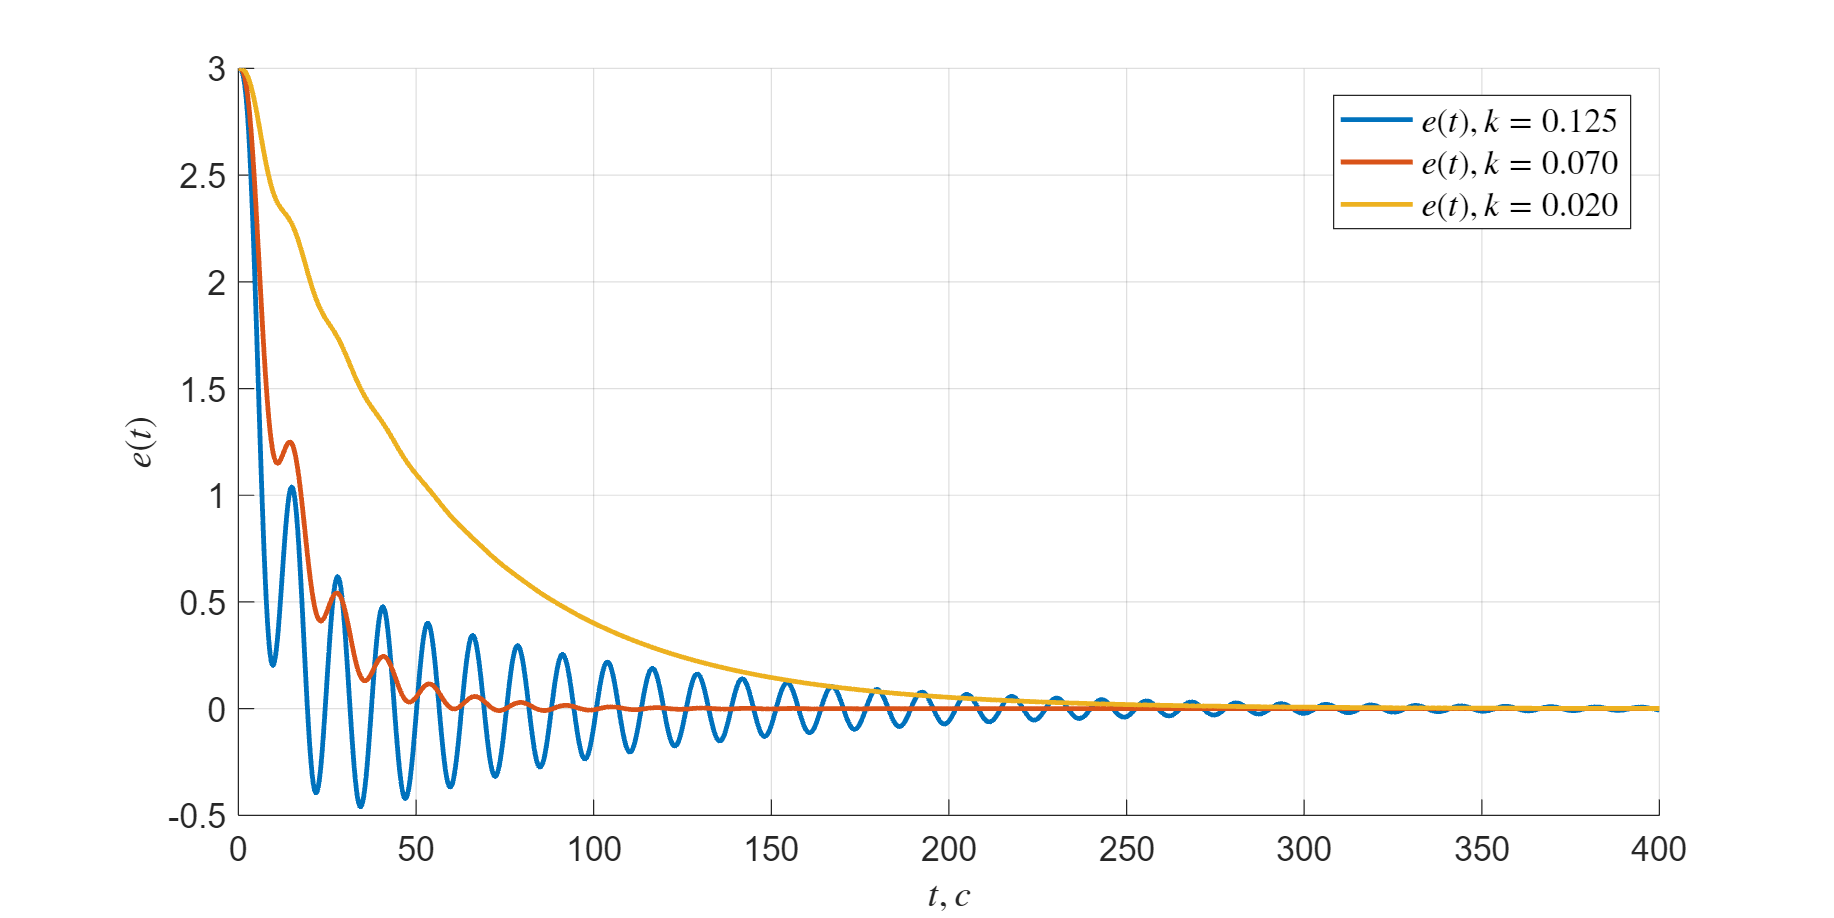

figure;
set(gcf,'AutoResizeChildren','off');
hold on;

for i = 1:length(k_arr)
    k = k_arr(i);
    plot_4e = sim("lab4_41.slx", simtime);
    plot(plot_4e.e.Time, plot_4e.e.Data, LineWidth=2, LineStyle="-", ...
                DisplayName=sprintf('$e(t), k=%.3f$', k))
    hold on;
end

grid on;
legend(Location="best", FontSize=14, Interpreter="latex");
xlabel("$t, c$", Interpreter="latex");
ylabel("$e(t)$", Interpreter="latex");
set(gcf, Position=[150, 150, 1200, 600]);
set(gca, FontSize=14);

drawnow;
exportgraphics(gcf, "images/plot_41_err.png", Resolution=200)
hold off;

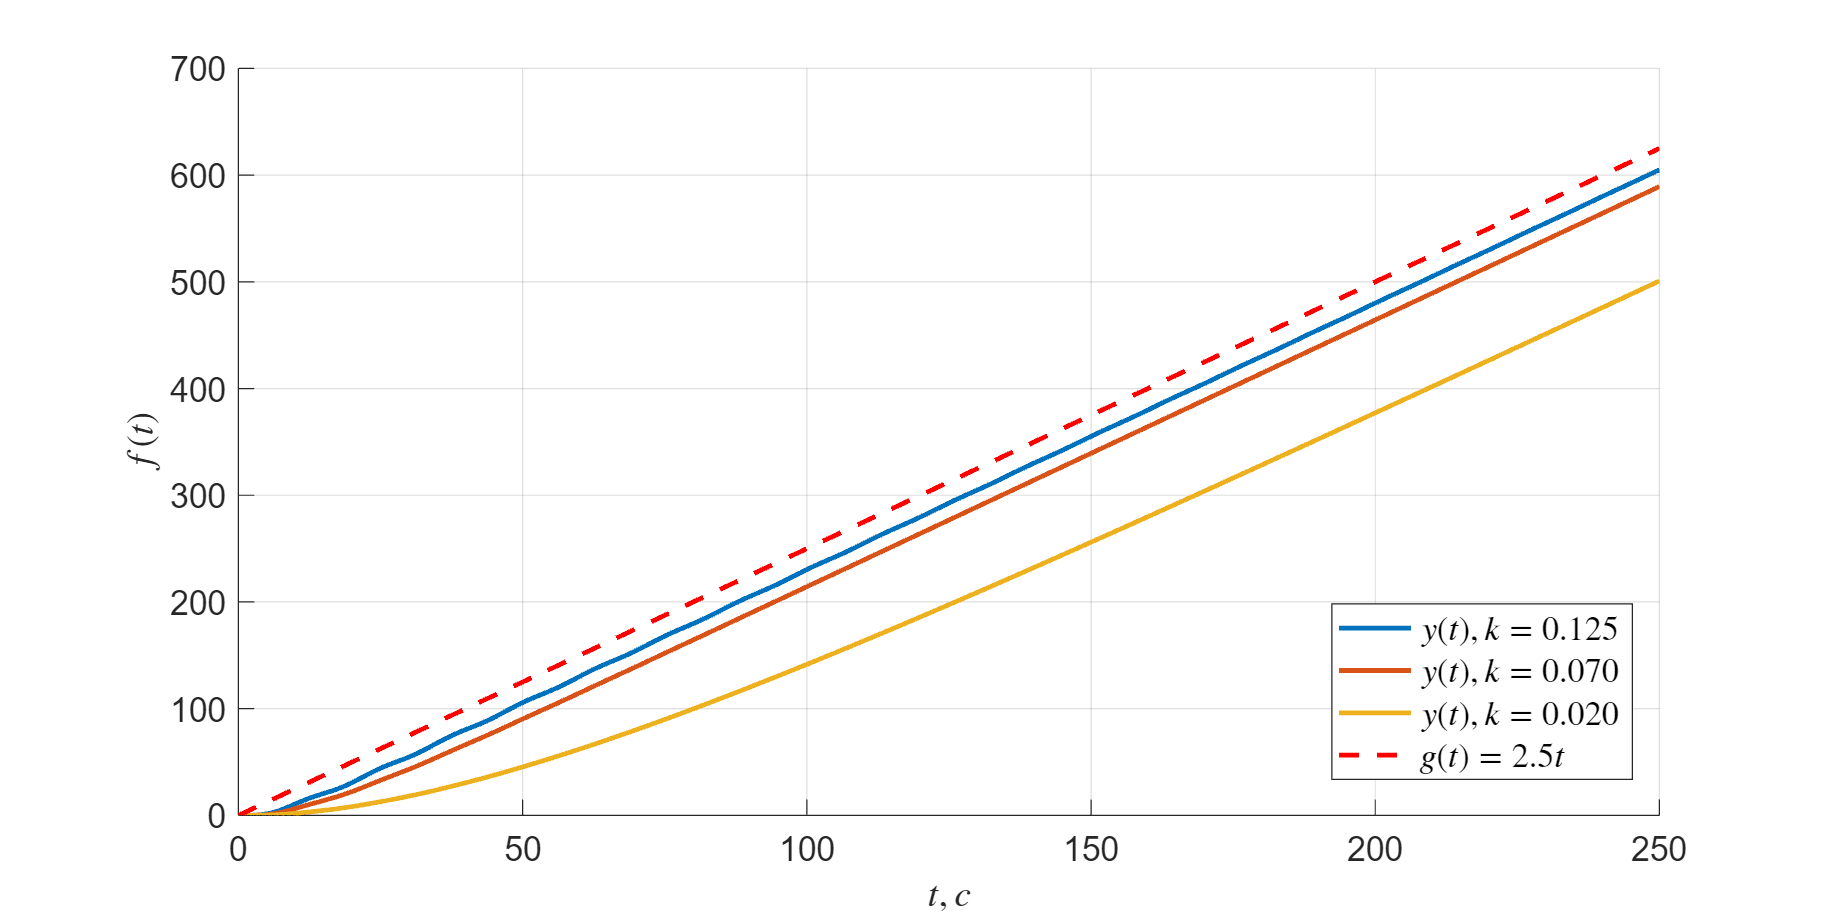

simtime = 250;
figure;
set(gcf,'AutoResizeChildren','off');
hold on;

for i = 1:length(k_arr)
    k = k_arr(i);
    plot_4 = sim("lab4_42.slx", simtime);
    plot(plot_4.y.Time, plot_4.y.Data, LineWidth=2, LineStyle="-", ...
                DisplayName=sprintf('$y(t), k=%.3f$', k))
    hold on;
end
plot_42 = sim("lab4_42.slx", simtime);
plot(plot_42.g.Time, plot_42.g.Data, LineWidth=2, color="red", LineStyle="--", ...
            DisplayName='$g(t)=2.5t$')
hold on;

grid on;
legend(Location="best", FontSize=14, Interpreter="latex");
xlabel("$t, c$", Interpreter="latex");
ylabel("$f(t)$", Interpreter="latex");
set(gcf, Position=[100, 100, 1200, 600]);   
set(gca, FontSize=14);

drawnow;
exportgraphics(gcf, "images/plot_42.png", Resolution=200)
hold off;

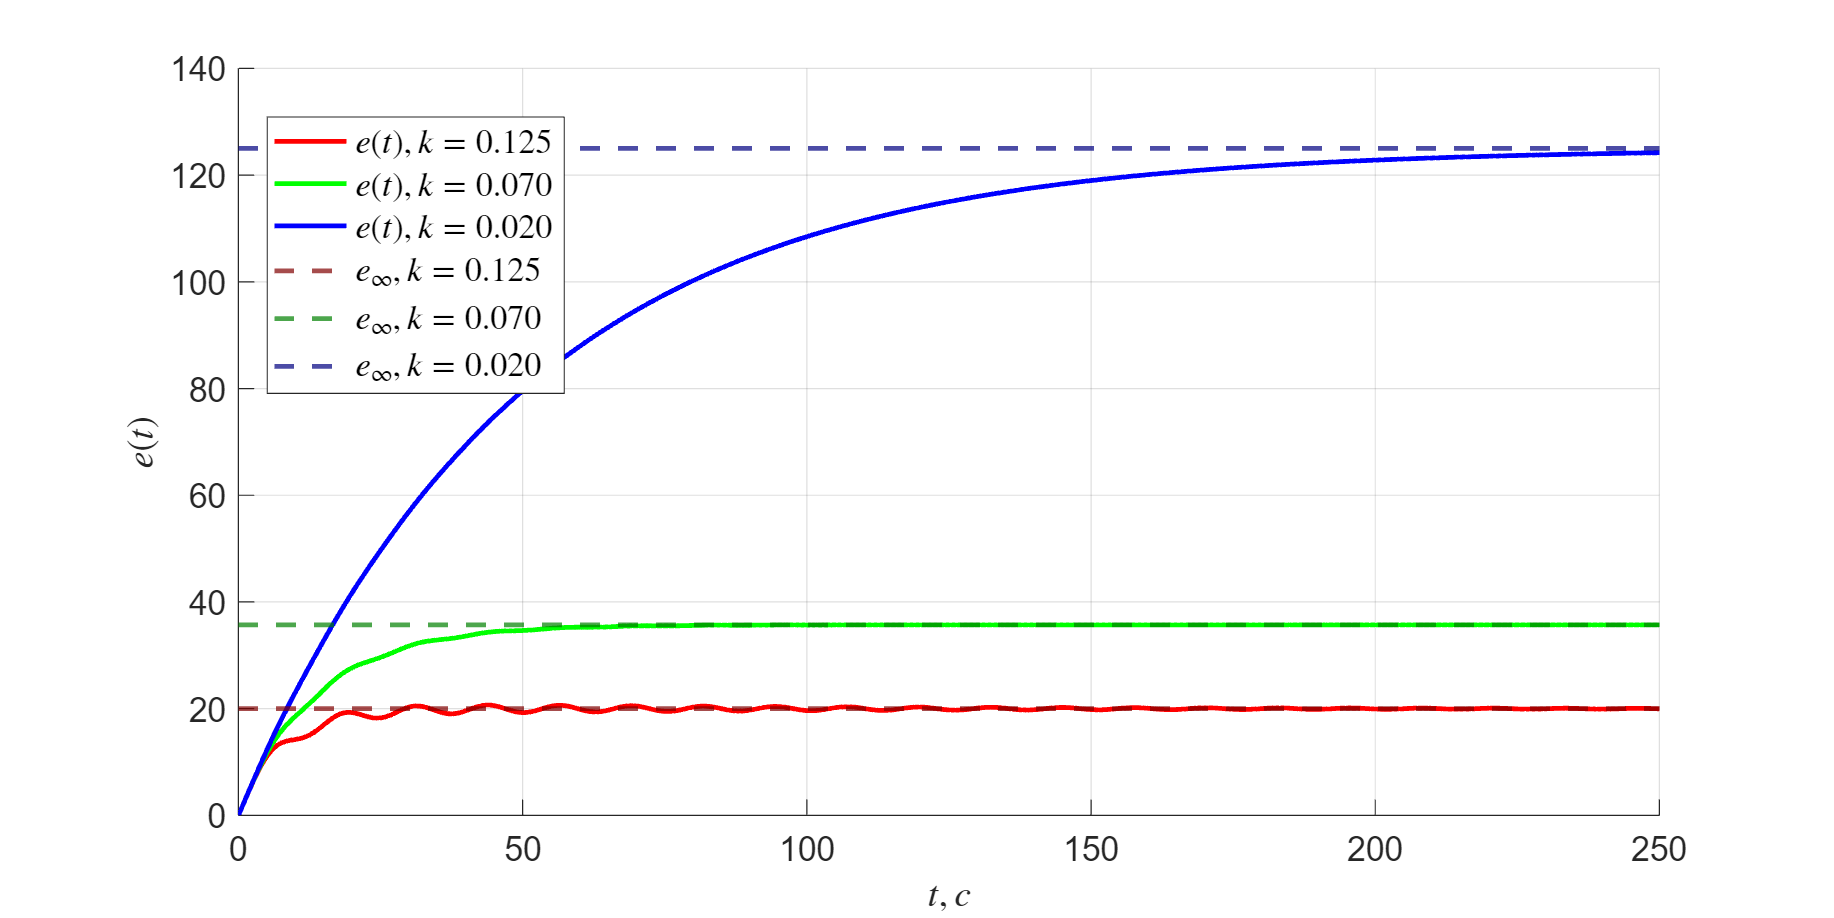

e_inf4 = [ 20, 35.7, 125]; 

figure;
set(gcf,'AutoResizeChildren','off');
hold on;
colors = hsv(length(k_arr));

for i = 1:length(k_arr)
    k = k_arr(i);
    plot_4e = sim("lab4_42.slx", simtime);
    plot(plot_4e.e.Time, plot_4e.e.Data, LineWidth=2, LineStyle="-", ...
                DisplayName=sprintf('$e(t), k=%.3f$', k), Color=colors(i,:))
    darkColor = colors(i,:) * (1 - 0.5);

    yline(e_inf4(i), '--', Color=darkColor, LineWidth=2, ...
        DisplayName=sprintf('$e_{\\infty}, k=%.3f$', k));

    hold on;
end

grid on;
legend(Location="best", FontSize=14, Interpreter="latex");
xlabel("$t, c$", Interpreter="latex");
ylabel("$e(t)$", Interpreter="latex");
set(gcf, Position=[150, 150, 1200, 600]);
set(gca, FontSize=14);

drawnow;
exportgraphics(gcf, "images/plot_42_err.png", Resolution=200)
hold off;

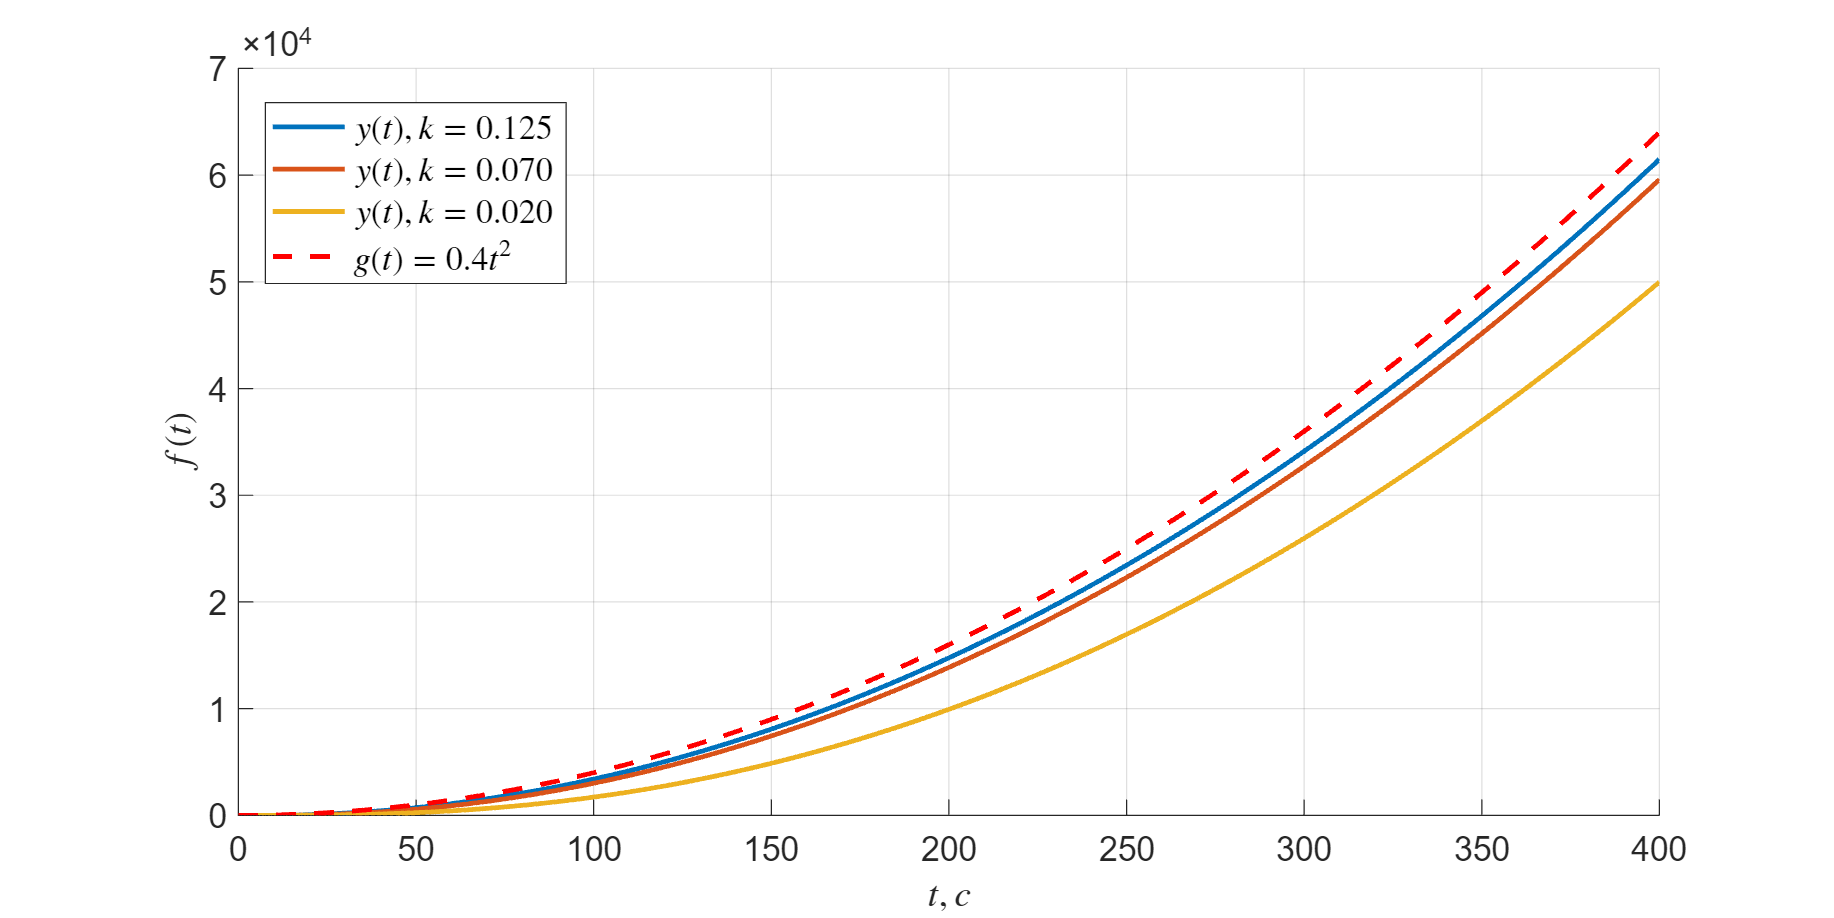

simtime = 400;
figure;
set(gcf,'AutoResizeChildren','off');
hold on;

for i = 1:length(k_arr)
    k = k_arr(i);
    plot_4 = sim("lab4_43.slx", simtime);
    plot(plot_4.y.Time, plot_4.y.Data, LineWidth=2, LineStyle="-", ...
                DisplayName=sprintf('$y(t), k=%.3f$', k))
    hold on;
end
plot_43 = sim("lab4_43.slx", simtime);
plot(plot_43.g.Time, plot_43.g.Data, LineWidth=2, color="red", LineStyle="--", ...
            DisplayName='$g(t)=0.4t^2$')
hold on;

grid on;
legend(Location="best", FontSize=14, Interpreter="latex");
xlabel("$t, c$", Interpreter="latex");
ylabel("$f(t)$", Interpreter="latex");
set(gcf, Position=[100, 100, 1200, 600]);   
set(gca, FontSize=14);

drawnow;
exportgraphics(gcf, "images/plot_43.png", Resolution=200)
hold off;

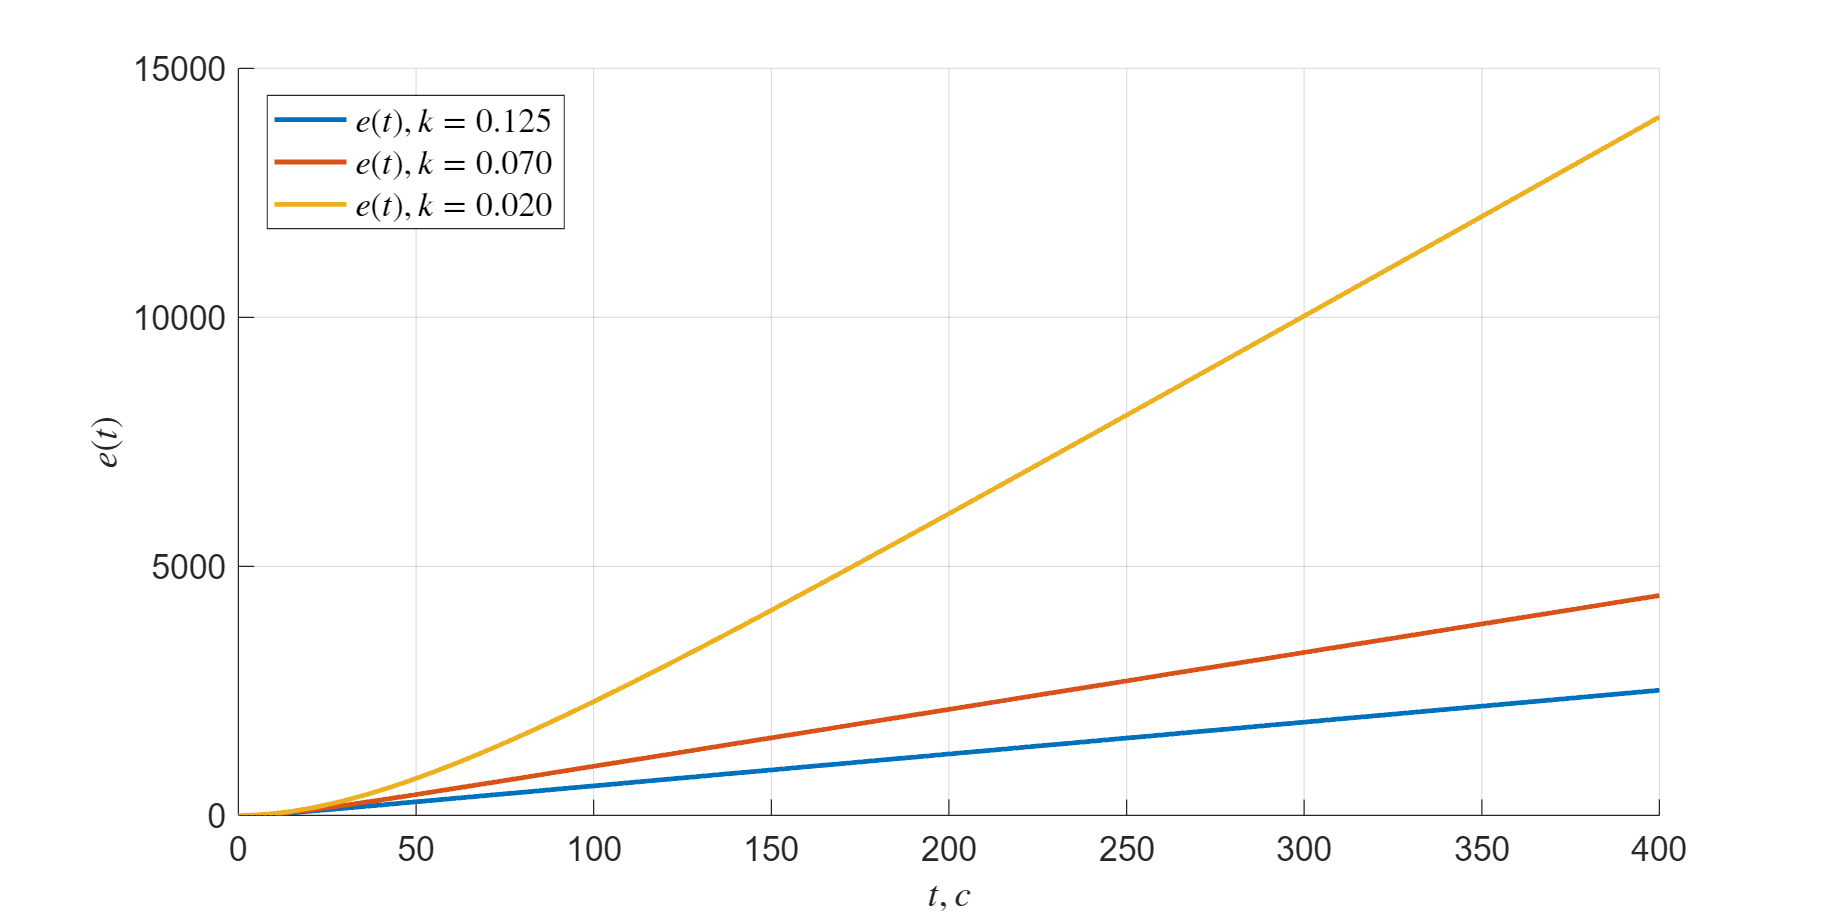

figure;
set(gcf,'AutoResizeChildren','off');
hold on;

for i = 1:length(k_arr)
    k = k_arr(i);
    plot_4e = sim("lab4_43.slx", simtime);
    plot(plot_4e.e.Time, plot_4e.e.Data, LineWidth=2, LineStyle="-", ...
                DisplayName=sprintf('$e(t), k=%.3f$', k))
    hold on;
end

grid on;
legend(Location="best", FontSize=14, Interpreter="latex");
xlabel("$t, c$", Interpreter="latex");
ylabel("$e(t)$", Interpreter="latex");
set(gcf, Position=[150, 150, 1200, 600]);
set(gca, FontSize=14);

drawnow;
exportgraphics(gcf, "images/plot_43_err.png", Resolution=200)
hold off;

# Задание 5

\section{Задача слежения для системы с астатизмом первого порядка (ПИ-регулятор)}

`Рассмотрим замкнутую систему, заданную структурной схемой на рисунке ???ВЫШЕ???, где`


$$H(s) = \frac{k_\text{И}}{s} + k_\text{П}$$


`- пропорционально-интегральный регулятор. Варианты передаточной функции объекта управления `$W(s)$` и характеристики задающего воздействия `$g(t)$` приведены в `**Таблице 1 **инструкции по выполнению лабораторной работы`. Зададимся не менее чем двумя значениями каждого из параметров `$k_\text{И}$` и `$k_\text{П}$` и составим все возможные комбинации пар выбранных значений параметров (т.е. не менее четырёх комбинаций). Все пары параметров должны обеспечивать асимптотически устойчивую замкнутую систему.`

`Исследуем режим движения с постоянной скоростью при `$g(t) = V t$`: выполним моделирование для выбранных значений `$k$`, а также аналитически определим предельное значение ошибки `$e_{уст}$` для каждого значения `$k$`. Сопоставим результаты между собой и сделаем выводы.`

`Исследуем режим слежения за гармоническим сигналом при `$g(t) = a \sin(\omega t)$`: выполним моделирование для выбранных значений `$k$`. Сопоставим результаты между собой и сделаем выводы.`

Возьмём из таблицы для варианта 27 передаточную функцию и параметры управляющего воздействия:


$$W(s) = \frac{1}{4s^2 + 0.6s + 1},\quad V = 2.5, \quad A\sin(\omega t)=3\sin(0.4t)$$


Передаточная функция замкнутой системы:


$$W_{g \rightarrow y}(s) = \frac{W(s) H(s)}{1 + W(s) H(s)} = \frac{\left(k_П + \frac{k_И}{s}\right) \cdot \frac{1}{4s^2 + 0.6s + 1}}{1 + \left(k_П + \frac{k_И}{s}\right) \cdot \frac{1}{4s^2 + 0.6s + 1}} = \frac{k_П s + k_И}{s(4s^2 + 0.6s + 1) + k_П s + k_И}=\\
= \frac{k_П s + k_И}{4s^3 + 0.6s^2 + (1 + k_П)s + k_И}$$


Найдем такие $k$, при которых замкнутая система является ассимптотически устойчивой.

$4s^3 + 0.6s^2 + (1 + k_П)s + k_И = 0$, воспользуемся критерием Гурвица, матрица Гурвица:


$$A=\pmatrix{0.6 & k_И & 0 \cr
4 & 1 + k_П & 0 \cr
0 & 0.6 & k_И}$$


Ведущие угловые миноры матрицы Гурвица: $\Delta_1 = 0.6, \quad \Delta_2 = 0.6(1 + k_П) - 4k_И, \quad \Delta_3 = k_И \cdot \Delta_2 = k_И(0.6(1 + k_П) - 4k_И)$

Следовательно, система ассимптотически устойчива при:


$$\begin{cases}
k_И > 0 \\
\quad 0.6(1 + k_П) - 4k_И > 0 \\
k_П>-1
\end{cases}
\quad \Rightarrow 
\begin{cases}
k_И  \in \left(0,\ 0.15(1 + k_П)\right) \\
k_П>-1
\end{cases}$$


Зададимся значениями $k_П = \{1, 2\}$`, `$k_И = \{0.1, 0.2\}$`. `Таким образом, рассмотрим комбинации параметров: $(k_П, k_И) = (1, 0.1), \quad (1, 0.2), \quad (2, 0.1), \quad (2, 0.2)$.

Проведем исследование для двух режимов работы.

**Движение с постоянной скоростью: **$G(s)=\frac{V}{s^2}$.

Аналитически определим предельное значение ошибки $e_{уст}$ для каждого значения $k$:

Ошибка слежения:


$$E(s)=\frac{1}{1+W(s)H(s)}G(s)=\frac{1}{1 + \left(k_П + \frac{k_И}{s}\right) \cdot \frac{1}{4s^2 + 0.6s + 1}} \cdot \frac{V}{s^2} = \frac{s(4s^2 + 0.6s + 1)}{s(4s^2 + 0.6s + 1) + k_П s + k_И} \cdot \frac{V}{s^2}=\\
=\frac{V(4s^2 + 0.6s + 1)}{s(4s^3 + 0.6s^2 + (1 + k_П)s + k_И)}$$


Согласно теореме о конечном значении, если все полюса $s\cdot E(s)$ имеют отрицательную вещественную часть, $\lim_{t\rightarrow+\infty}{y(t)=\lim_{s\rightarrow0}{sY(s)}$.

$s\cdot E(s)= \frac{V(4s^2 + 0.6s + 1)}{4s^3 + 0.6s^2 + (1 + k_П)s + k_И}$, полюса данной передаточной функции отрицательны, так как ранее мы уже подбирали диапазон $k$, соответствующий отрицательным полюсам передаточной функции с таким же знаменателем. Можем применнить теорему о конечном значении и найти установившуюся ошибку:


$$e_{\text{уст}}=\lim_{s\rightarrow0}{s\cdot E(s)}=\lim_{s \to 0} \frac{V(4s^2 + 0.6s + 1)}{4s^3 + 0.6s^2 + (1 + k_П)s + k_И} =\frac{V(4\cdot0^2 + 0.6\cdot0 + 1)}{4\cdot0^3 + 0.6\cdot0^2 + (1 + k_П)\cdot0 + k_И}= \frac{V}{k_И}$$


Как видим, пропорциональный коэффициент не влияет на значение установившейся ошибки.

Рассчитаем для каждого $k_И$:

- 
$$k_И=0.1,\quad e_{\text{уст}}=\frac{2.5}{0.1}=25$$


- 
$$k_И=0.2,\quad e_{\text{уст}}=\frac{2.5}{0.2}=12.5$$


Выполним моделирование. Структурная схема представлена на рис. ???.

???РИСУНОК???

Графики входа и выходов на рис. ???.

???РИСУНОК???

Графики ошибки на рис. ???.

???РИСУНОК???

**Слежение за гармоническим сигналом: **$G(s)=\frac{a\omega}{p^2+\omega^2}$.

Выполним моделирование. Структурная схема представлена на рис. ???.

???РИСУНОК???

Графики входа и выходов на рис. ???.

???РИСУНОК???

Графики ошибки на рис. ???.

???РИСУНОК???

**Выводы**

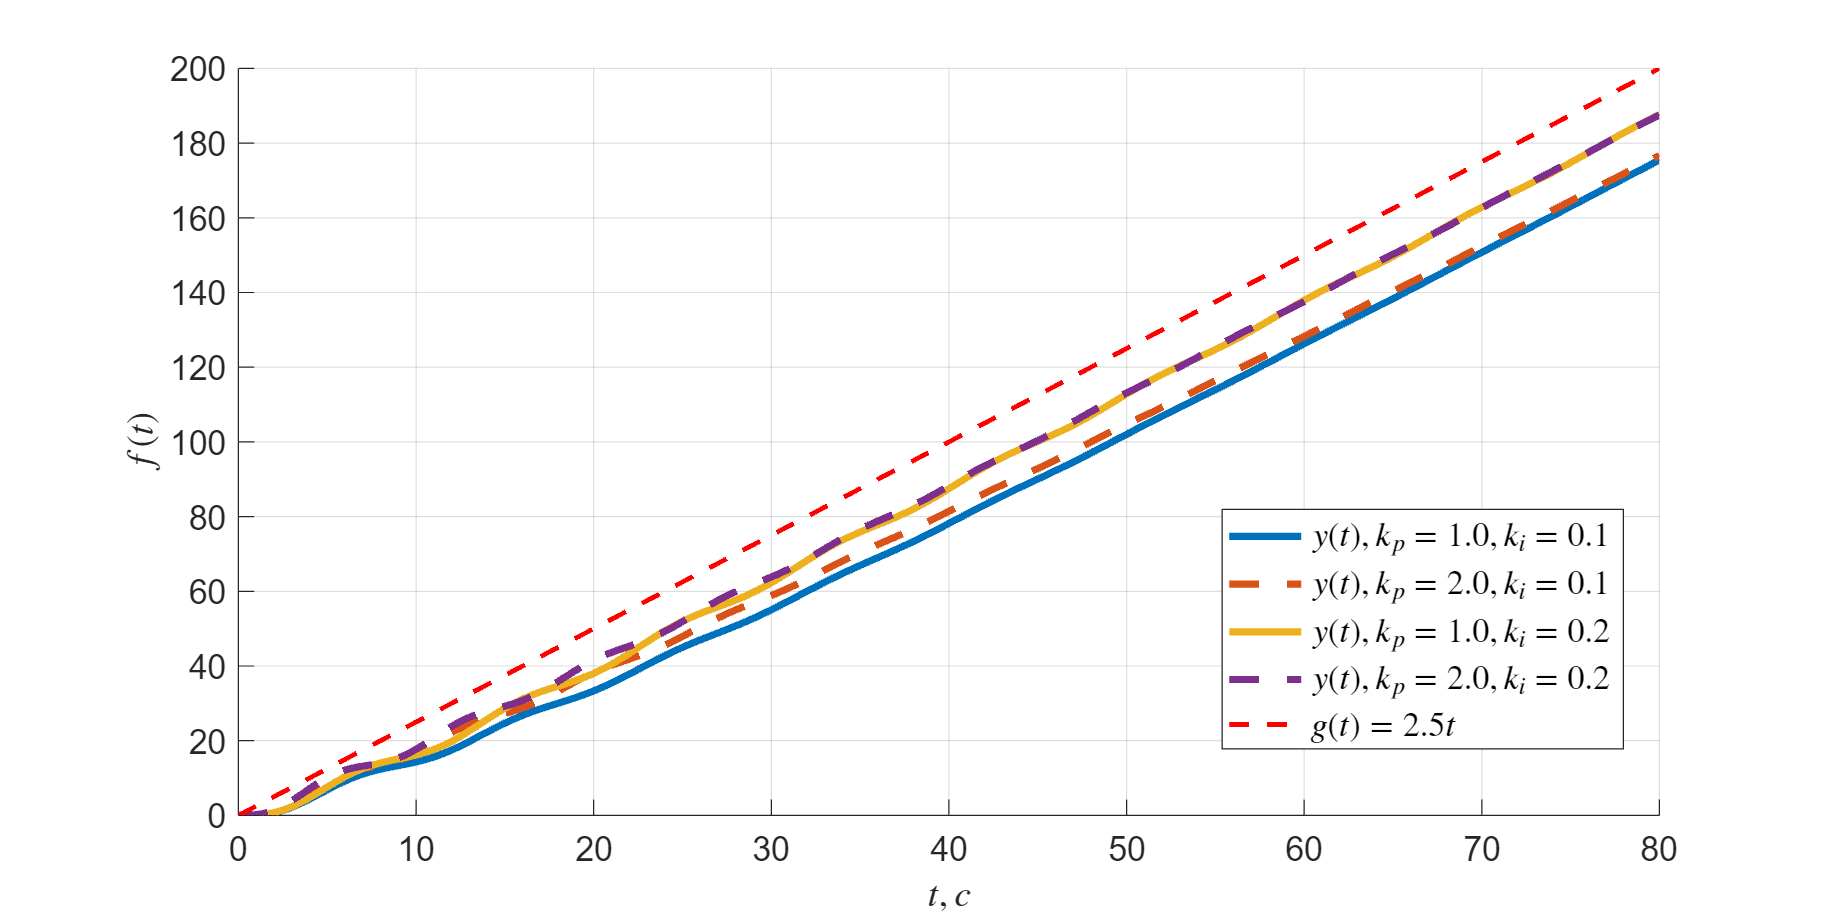

k_arr = [1, 0.1; 2, 0.1; 1, 0.2; 2, 0.2];
A = 3;
V = 2.5;
w = 0.4;

simtime = 80;
figure;
set(gcf,'AutoResizeChildren','off');
hold on;
ls = ["-", "--", "-", "--"];

for i = 1:size(k_arr,1)
    k_p = k_arr(i,1);
    k_i = k_arr(i,2);

    plot_5 = sim("lab4_51.slx", simtime);
    plot(plot_5.y.Time, plot_5.y.Data, LineWidth=3, LineStyle=ls(i), ...
                DisplayName=sprintf('$y(t), k_p=%.1f, k_i=%.1f$', k_p, k_i))
    hold on;
end
plot_51 = sim("lab4_51.slx", simtime);
plot(plot_51.g.Time, plot_51.g.Data, LineWidth=2, color="red", LineStyle="--", ...
            DisplayName='$g(t)=2.5t$')
hold on;

grid on;
legend(Location="best", FontSize=14, Interpreter="latex");
xlabel("$t, c$", Interpreter="latex");
ylabel("$f(t)$", Interpreter="latex");
set(gcf, Position=[100, 100, 1200, 600]);   
set(gca, FontSize=14);

drawnow;
exportgraphics(gcf, "images/plot_51.png", Resolution=200)
hold off;

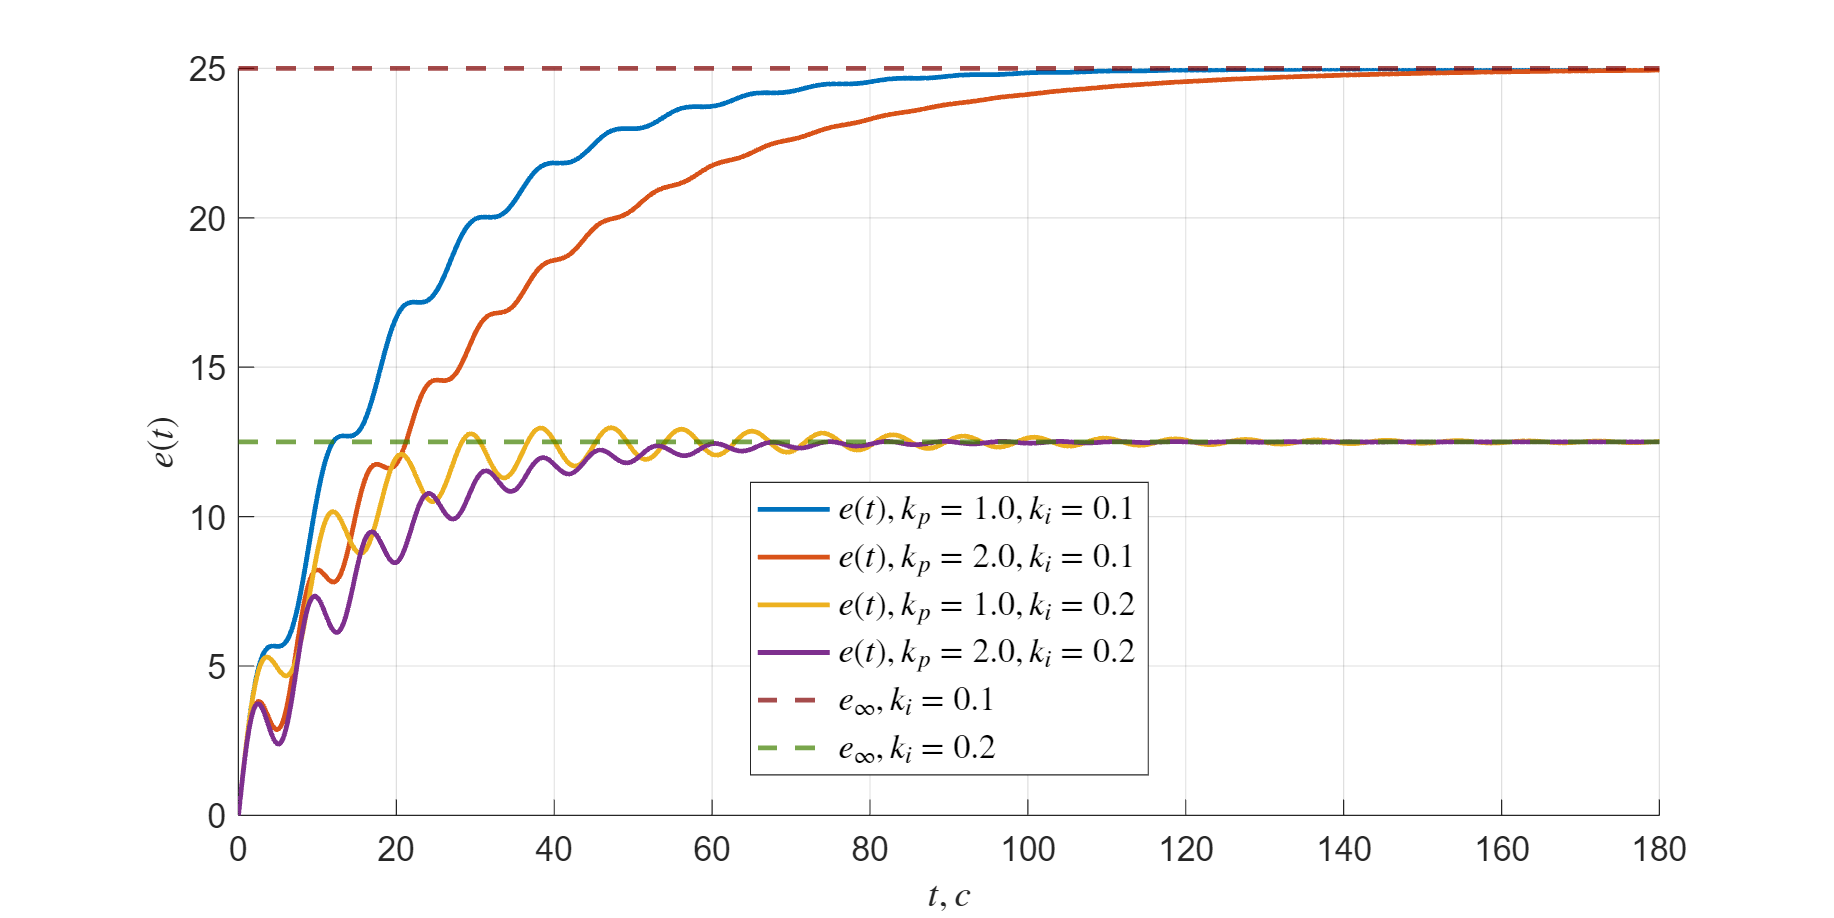

e_inf5 = [ 25, 12.5]; 
ki = [ 0.1, 0.2 ];
simtime = 180;
figure;
set(gcf,'AutoResizeChildren','off');
hold on;
colors = hsv(length(k_arr));

for i = 1:2
    darkColor = colors(i,:) * (1 - 0.5);
    yline(e_inf5(i), '--', Color=darkColor, LineWidth=2, ...
        DisplayName=sprintf('$e_{\\infty}, k_i=%.1f$', ki(i)));

    hold on;
end

for i = 1:size(k_arr,1)
    k_p = k_arr(i,1);
    k_i = k_arr(i,2);
    plot_5e = sim("lab4_51.slx", simtime);
    plot(plot_5e.e.Time, plot_5e.e.Data, LineWidth=2, LineStyle="-", ...
                DisplayName=sprintf('$e(t), k_p=%.1f, k_i=%.1f$', k_p, k_i))

    hold on;
end

grid on;
legend(Location="best", FontSize=14, Interpreter="latex");
xlabel("$t, c$", Interpreter="latex");
ylabel("$e(t)$", Interpreter="latex");
set(gcf, Position=[150, 150, 1200, 600]);
set(gca, FontSize=14);

drawnow;
exportgraphics(gcf, "images/plot_51_err.png", Resolution=200)
hold off;

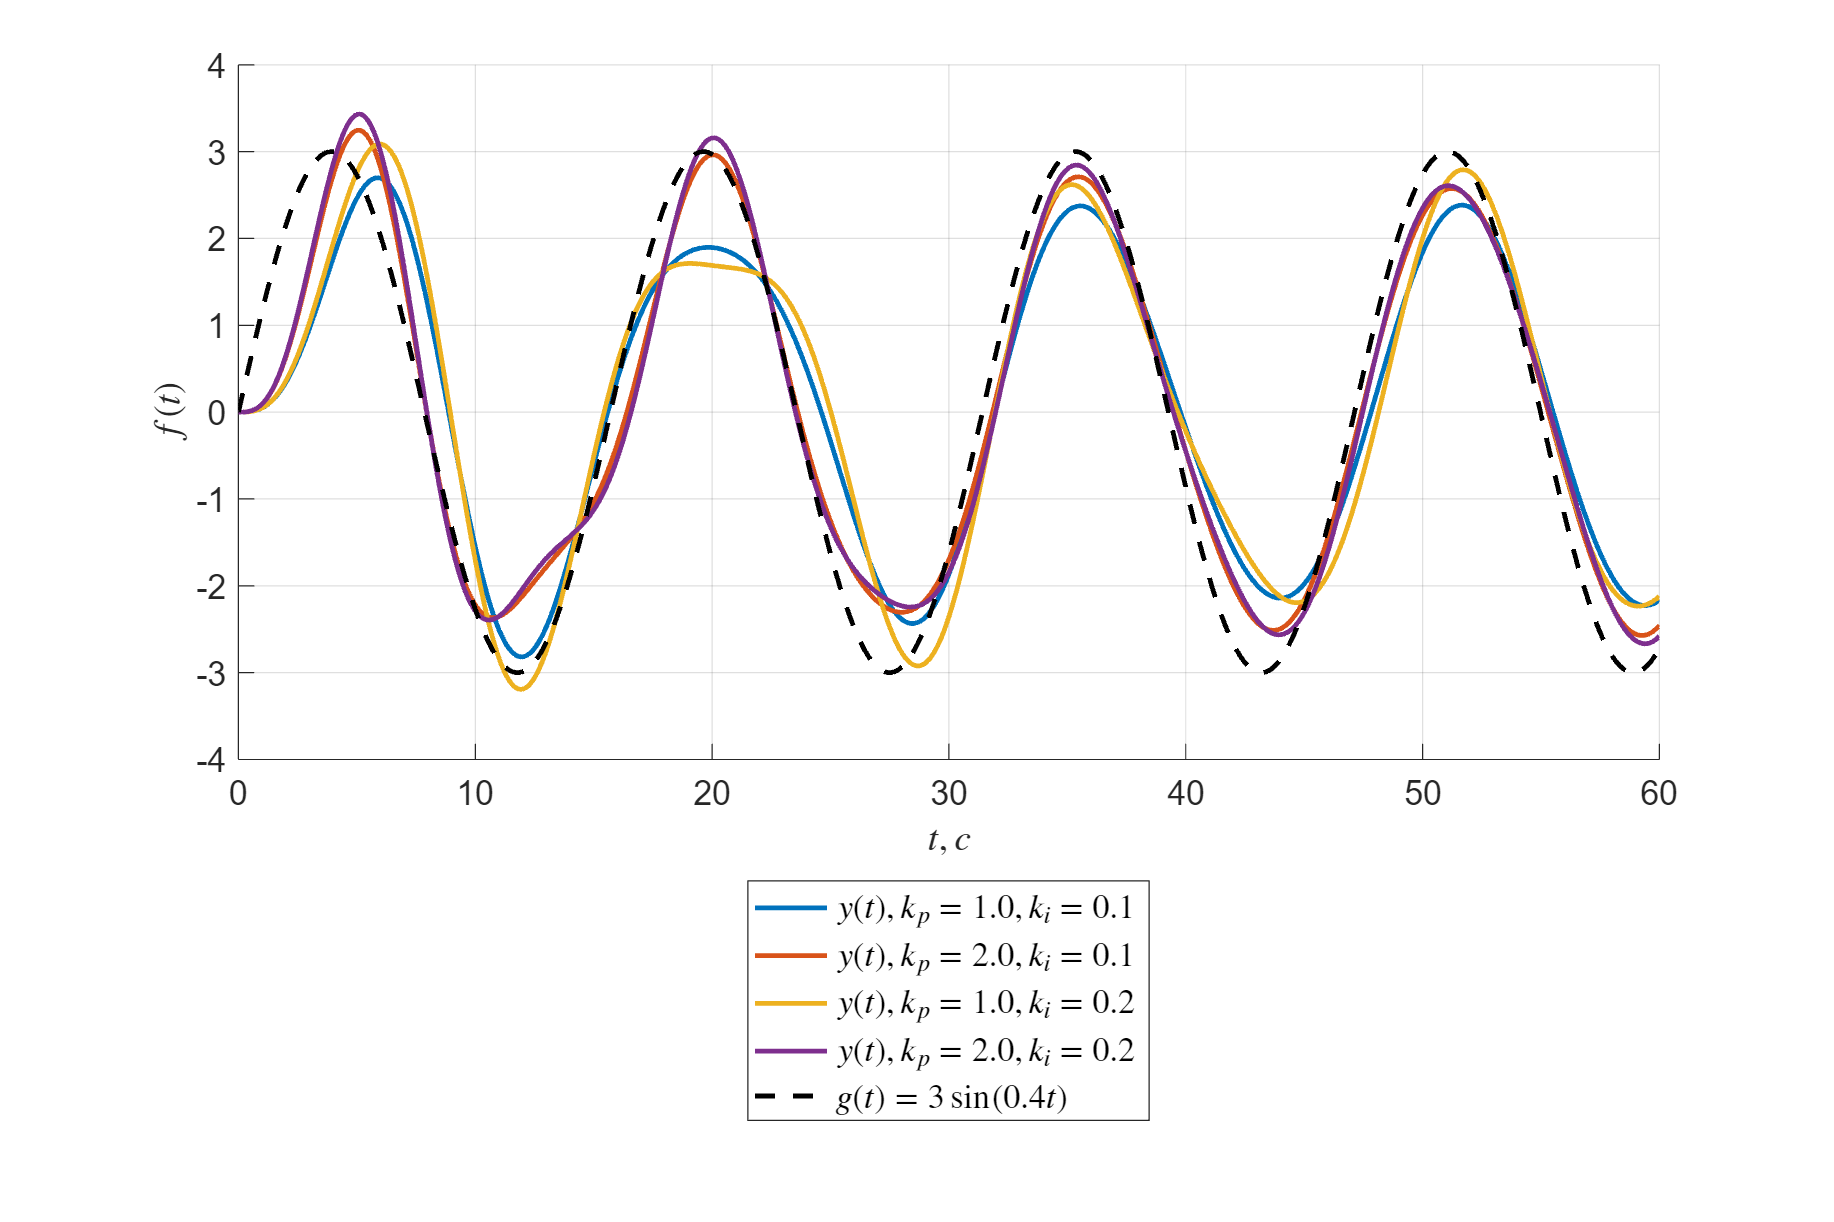

k_arr = [1, 0.1; 2, 0.1; 1, 0.2; 2, 0.2];
A = 3;
V = 2.5;
w = 0.4;
simtime = 60;
figure;
set(gcf,'AutoResizeChildren','off');
hold on;

for i = 1:size(k_arr,1)
    k_p = k_arr(i,1);
    k_i = k_arr(i,2);
    plot_5 = sim("lab4_52.slx", simtime);
    plot(plot_5.y.Time, plot_5.y.Data, LineWidth=2, LineStyle="-", ...
                DisplayName=sprintf('$y(t), k_p=%.1f, k_i=%.1f$', k_p, k_i))
    hold on;
end
plot_52 = sim("lab4_52.slx", simtime);
plot(plot_52.g.Time, plot_52.g.Data, LineWidth=2, color="black", LineStyle="--", ...
            DisplayName='$g(t)=3\sin(0.4t)$')
hold on;

grid on;
legend(Location="southoutside", FontSize=14, Interpreter="latex");
xlabel("$t, c$", Interpreter="latex");
ylabel("$f(t)$", Interpreter="latex");
set(gcf, Position=[100, 100, 1200, 800]);   
set(gca, FontSize=14);

drawnow;
exportgraphics(gcf, "images/plot_52.png", Resolution=200)
hold off;

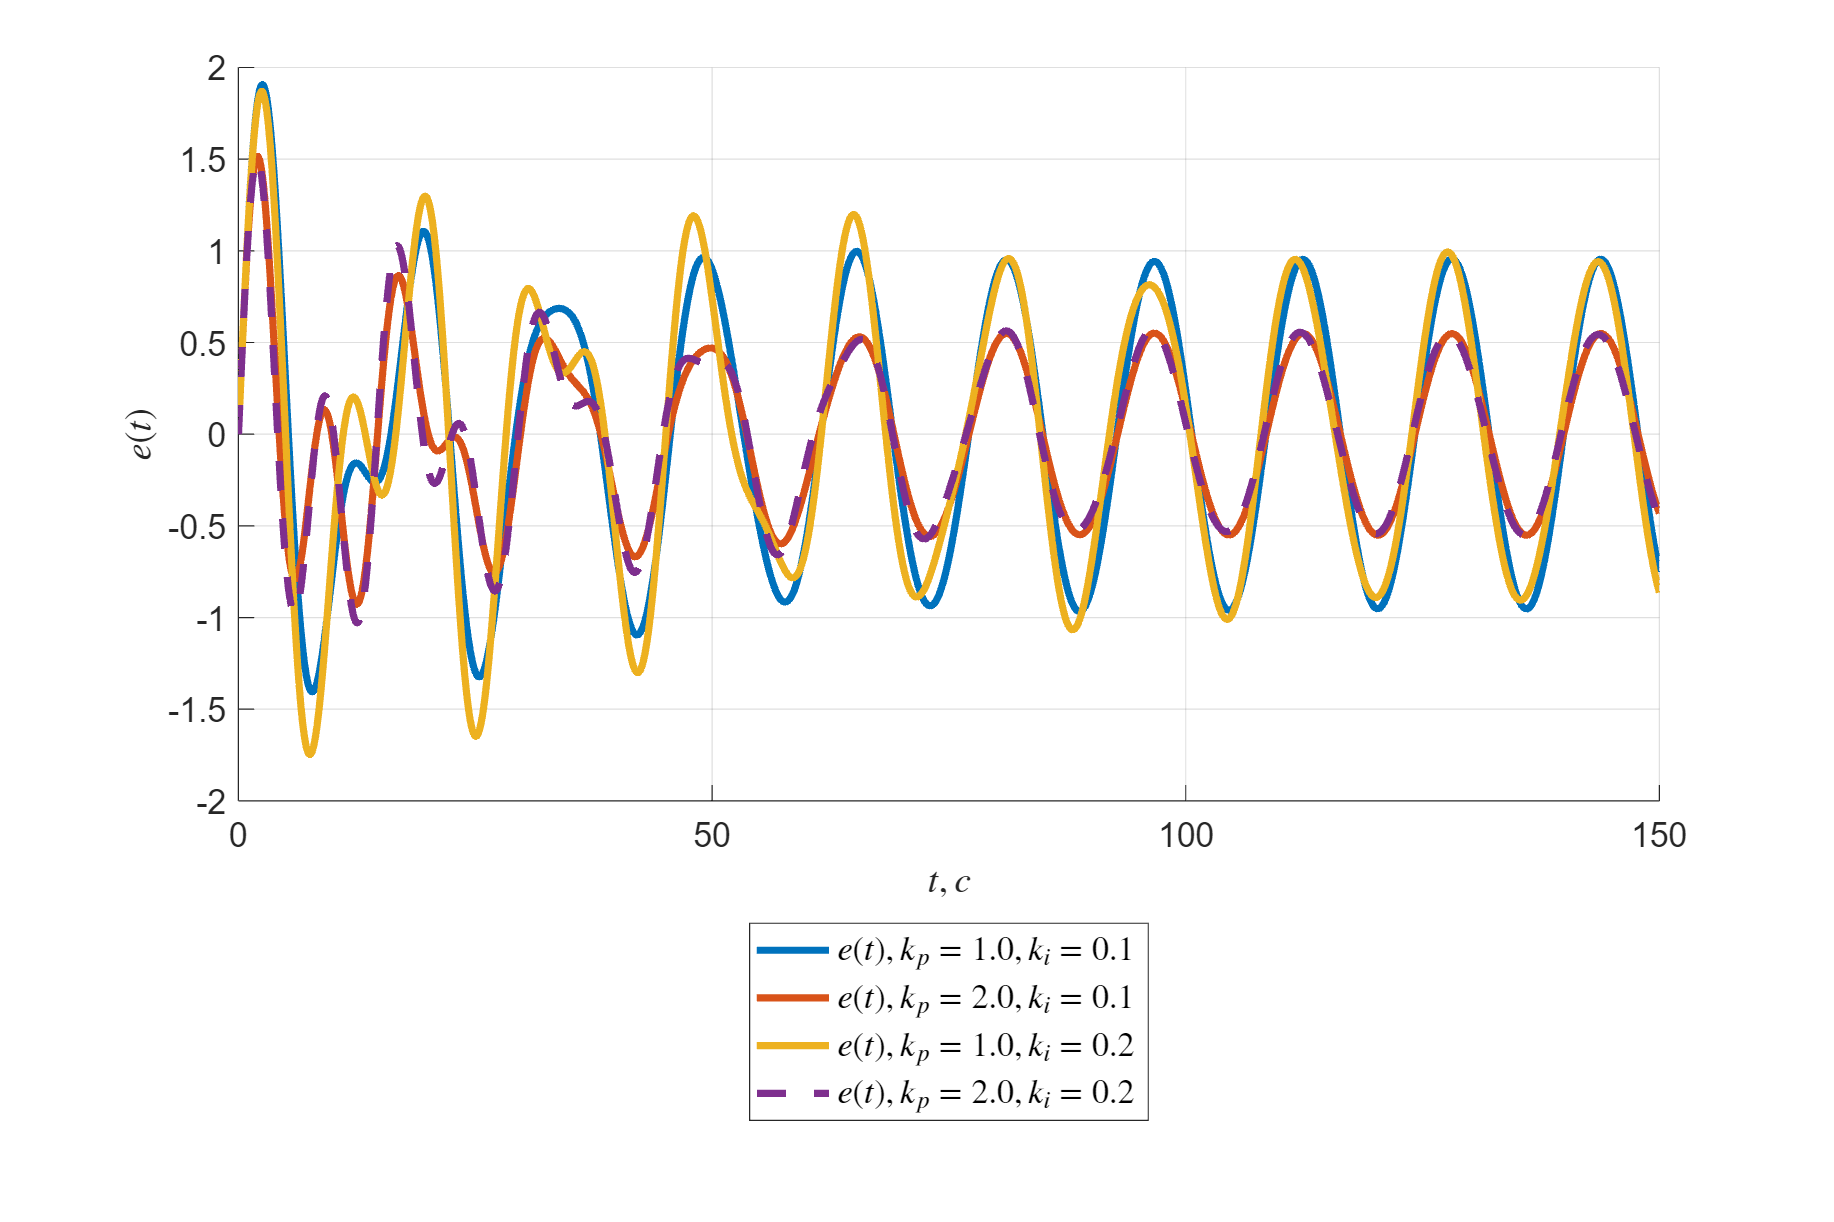

simtime = 150;
figure;
set(gcf,'AutoResizeChildren','off');
hold on;
colors = hsv(length(k_arr));

ls = ["-", "-", "-", "--"];
for i = 1:size(k_arr,1)
    k_p = k_arr(i,1);
    k_i = k_arr(i,2);
    plot_5e = sim("lab4_52.slx", simtime);
    plot(plot_5e.e.Time, plot_5e.e.Data, LineWidth=3, LineStyle=ls(i), ...
                DisplayName=sprintf('$e(t), k_p=%.1f, k_i=%.1f$', k_p, k_i))

    hold on;
end

grid on;
legend(Location="southoutside", FontSize=14, Interpreter="latex");
xlabel("$t, c$", Interpreter="latex");
ylabel("$e(t)$", Interpreter="latex");
set(gcf, Position=[150, 150, 1200, 800]);
set(gca, FontSize=14);

drawnow;
exportgraphics(gcf, "images/plot_52_err.png", Resolution=200)
hold off;